typeDir = dir("analysis/queue/")

typeDir = 13×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


sparkDensityData = 'sparkDensityDatatest.xlsx'

sparkDensityData = 'sparkDensityDatatest.xlsx'


import sparkMask.*
import sparkMaskMorph.*
import sparkMaskMorphBright.*
import sparkMaskNorm.*
import sparkMaskRGB.*



sparkMatrix = {'sparkArea', 'totalArea', 'sparkDensity','image','sparkLengthMean';}

sparkMatrix = 1×5 cell array
    {'sparkArea'}    {'totalArea'}    {'sparkDensity'}    {'image'}    {'sparkLengthMean'}


fileFolder = 'Analysis/queue/Wrought'

fileNames = 9×1 cell array
    {'ENGR 140B Lab 1 - Crop - Wroght Iron - 40.jpg'}
    {'ENGR 140B Lab 1 - Crop - Wroght Iron - 41.jpg'}
    {'ENGR 140B Lab 1 - Crop - Wroght Iron - 42.jpg'}
    {'ENGR 140B Lab 1 - Crop - Wroght Iron - 43.jpg'}
    {'ENGR 140B Lab 1 - Crop - Wroght Iron - 44.jpg'}
    {'ENGR 140B Lab 1 - Crop - Wroght Iron - 45.jpg'}
    {'ENGR 140B Lab 1 - Crop - Wroght Iron - 46.jpg'}
    {'ENGR 140B Lab 1 - Crop - Wroght Iron - 47.jpg'}
    {'ENGR 140B Lab 1 - Crop - Wroght Iron - 48.jpg'}



tempSpark =

     []



imgSrc = 1220×1220×3 uint8 array
imgSrc(:,:,1) =

    86    96   106   106   106   109   111   107   106   120   118   100    88    89    90    85    89   106   111   101   102   116   117   104   109    97   101    97    78    83    99    96    97   100   100    96    98   104   106   104    94    86    86    82    70    73    83    82   100    92    93   101    99    90    89    97    90    88    85    82    81    80    80    79    85    93   103   106   103    99    98   100    95    81    76    85    95    98    96    95    97   100   104   105   103    99    92    89    87    80    78    79    81    85    92   101   115   116   112   103    99    98    87    76    80    83    89    92    96   103   110   116    95    96    99   101    93    82    83    89    76    73    88   106   103    84    81    93    84    84    93   103   102    91    84    83    89    95   102   109   113   112   108   105    95   102    95    88    89    84    77    84    84    83    91    99    95    98  

imgSrcGray = 1220×1220 uint8 matrix
   37   48   57   57   56   58   58   54   57   73   73   54   41   44   46   41   37   56   62   51   52   67   68   54   64   51   55   51   30   35   53   49   53   56   56   52   54   60   63   60   55   46   46   42   29   32   43   42   57   48
   34   43   47   46   45   48   49   47   40   49   52   38   29   31   35   35   24   45   54   41   31   38   47   47   49   37   41   36   19   23   40   36   44   47   46   42   41   45   45   41   41   33   32   29   18   22   33   34   48   36
   30   36   38   34   34   38   41   38   26   30   30   23   15   14   20   26   29   31   27   23   25   33   36   34   35   24   26   22    7   11   26   24   34   37   36   31   29   31   29   23   27   21   19   14    9   15   26   29   37   26
   24   30   31   27   27   32   33   30   24   21   19   16    9    2    8   19   26   20   18   24   35   37   32   24   26   18   18   14    3    8   19   19   23   29   30   25   25   27   25   20   21   16 

rimg = 1220×1220 uint8 matrix
    86    96   106   106   106   109   111   107   106   120   118   100    88    89    90    85    89   106   111   101   102   116   117   104   109    97   101    97    78    83    99    96    97   100   100    96    98   104   106   104    94    86    86    82    70    73    83    82   100    92
    79    87    92    91    92    96    99    97    85    94    95    83    73    73    76    76    73    92   100    88    79    86    94    94    92    81    84    80    63    68    83    80    88    91    90    86    85    89    89    85    79    72    71    68    58    62    72    73    91    80
    68    74    77    75    76    80    84    82    68    69    69    62    54    51    56    61    70    72    69    65    67    74    77    75    73    63    65    61    47    51    65    63    78    81    80    75    73    75    73    68    66    60    58    54    49    55    65    67    78    68
    57    62    65    63    63    69    71    68    59    56    52 

gimg = 1220×1220 uint8 matrix
   46   57   64   64   63   64   64   60   64   78   79   62   50   53   56   51   45   62   67   57   58   72   73   60   72   60   64   60   41   46   62   59   63   66   66   62   64   70   72   70   67   58   57   53   41   44   55   55   67   59
   45   53   56   55   54   57   57   55   49   58   61   48   40   42   47   47   34   53   61   49   40   47   55   55   60   49   52   48   31   36   51   48   54   57   56   52   51   55   55   51   54   46   44   40   30   35   46   48   59   48
   42   48   50   46   45   49   51   49   38   42   42   36   30   29   34   41   40   42   39   35   37   44   47   45   47   37   39   35   21   25   39   37   44   47   46   41   39   41   39   34   41   34   31   26   21   28   39   42   49   39
   39   44   45   41   41   45   45   42   39   36   34   32   25   20   25   35   40   34   32   38   48   50   45   38   41   33   33   30   20   24   34   34   35   40   41   37   37   39   37   32   35   30   24  

bimg = 1220×1220 uint8 matrix
   10   18   26   24   21   22   22   16   24   38   40   25   14   17   21   16    8   25   30   20   21   35   36   23   30   18   22   18    0    4   20   17   18   21   21   17   19   25   27   25   22   18   23   23   11   10   15   10   22   14
   10   18   22   19   17   18   19   15   13   22   26   16    9   11   17   17    1   20   28   16    7   14   22   22   22   11   14   10    0    0   13   10   16   19   18   14   13   17   17   13   14   11   15   16    6    6   11    8   20    9
   15   21   21   16   16   18   18   16   10   13   15    9    4    5   11   17   12   14   11    7    9   16   19   17   20   10   12    8    0    0   12   10   16   19   18   13   11   13   11    6   11    9   12   12    7    9   14   12   19    9
   17   22   21   18   17   19   20   15   15   12   12   12    5    1    8   18   19   13   11   17   27   29   24   17   21   13   13   10    0    4   14   14   14   19   20   16   16   18   16   11   12   12   12  

imgBrightness = 88.1431

imgBrightnessOffest = -67.4003

workingImg = 1220×1220 uint8 matrix
   0   0   0   0   0   0   0   0   0   6   6   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0

rimg = 1220×1220 uint8 matrix
    67    78    89    89    89    92    95    90    89   105   102    82    69    70    71    66    70    89    95    84    85   100   101    87    92    79    84    79    58    63    81    78    79    82    82    78    80    87    89    87    76    67    67    62    49    52    63    62    82    73
    59    68    73    72    73    78    81    79    66    76    77    63    52    52    56    56    52    73    82    69    59    67    76    76    73    61    65    60    41    47    63    60    69    72    71    67    66    70    70    66    59    51    50    47    36    40    51    52    72    60
    47    53    57    55    56    60    65    62    47    48    48    40    31    28    33    39    49    51    48    43    46    53    57    55    52    41    43    39    23    28    43    41    58    61    60    55    52    55    52    47    45    38    36    31    26    32    43    46    58    47
    35    40    43    41    41    48    50    47    37    33    29 

gimg = 1220×1220 uint8 matrix
   30   42   50   50   49   50   50   45   50   65   66   48   35   38   41   36   29   48   53   42   43   58   59   45   58   45   50   45   25   30   48   44   49   52   52   48   50   56   58   56   53   43   42   38   25   28   40   40   53   44
   29   38   41   40   39   42   42   40   33   43   46   32   24   26   31   31   17   38   46   33   24   31   40   40   45   33   37   32   14   19   36   32   39   42   41   37   36   40   40   36   39   30   28   24   13   18   30   32   44   32
   26   32   35   30   29   33   36   33   22   26   26   19   13   12   17   25   24   26   23   18   21   28   31   29   31   21   23   18    3    8   23   21   28   31   30   25   23   25   23   17   25   17   14    9    3   11   23   26   33   23
   23   28   29   25   25   29   29   26   23   19   17   15    8    2    8   18   24   17   15   22   32   35   29   22   25   16   16   13    2    6   17   17   18   24   25   21   21   23   21   15   18   13    6  

bimg = 1220×1220 uint8 matrix
    8   16   25   23   20   21   21   14   23   37   39   24   12   15   20   14    6   24   29   19   20   34   35   22   29   16   21   16    0    2   19   15   16   20   20   15   17   24   26   24   21   16   22   22    9    8   13    8   21   12
    8   16   21   17   15   16   17   13   11   21   25   14    7    9   15   15    0   19   27   14    5   12   21   21   21    9   12    8    0    0   11    8   14   17   16   12   11   15   15   11   12    9   13   14    4    4    9    6   19    7
   13   20   20   14   14   16   16   14    8   11   13    7    2    3    9   15   10   12    9    5    7   14   17   15   19    8   10    6    0    0   10    8   14   17   16   11    9   11    9    4    9    7   10   10    5    7   12   10   17    7
   15   21   20   16   15   17   19   13   13   10   10   10    3    0    6   16   17   11    9   15   26   28   23   15   20   11   11    8    0    2   12   12   12   17   19   14   14   16   14    9   10   10   10  

imgSum = 1220×1220 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   

imgInfo = 144×1 struct array with fields:
    Area
    MajorAxisLength


sparkLength =   117.4432   84.1877   55.9462   68.7620  154.7629  350.6923   20.1685   45.4817  114.4934   36.6742  334.2092  274.3870  197.7431   67.6885    8.1034  414.3751    6.4291  136.6566  355.2989  154.8549  319.8131  246.7909   30.6182   65.7858   21.3259   63.2769  150.9956    6.4291  981.1370   47.7165  352.3018  152.2502  330.6992   87.0670   33.8621  158.5397    4.7610  538.3684   11.3725  255.1982   98.2929   19.7310    4.7610   34.6550  192.1280    6.4291  358.4631   99.4158  549.6878    6.4291


indicies =     15    17    28    37    39    42    43    46    50    53    59    61    64    68    79    80    81    83    85    86    88    89    91    92    93    94    97    99   101   102   103   105   108   110   112   113   114   116   117   118   119   120   123   124   125   126   127   129   131   133


sparkLength =   117.4432   84.1877   55.9462   68.7620  154.7629  350.6923   20.1685   45.4817  114.4934   36.6742  334.2092  274.3870  197.7431   67.6885  414.3751  136.6566  355.2989  154.8549  319.8131  246.7909   30.6182   65.7858   21.3259   63.2769  150.9956  981.1370   47.7165  352.3018  152.2502  330.6992   87.0670   33.8621  158.5397  538.3684  255.1982   98.2929   34.6550  192.1280  358.4631   99.4158  549.6878  145.7521  324.8449   91.4994   32.3943  261.2298   45.2209   34.0540  301.5982   32.1087


sparkLenghtMean = 1.3210

sparkArea = 65400

totalArea = 1488400

sparkDensity = 0.0439

sparkInfo = 1×5 cell array
    {[65400]}    {[1488400]}    {[0.0439]}    {'ENGR 140B Lab 1 - Crop - Wroght Iron - 40.jpg'}    {[1.3210]}


tempSpark = 1×5 cell array
    {[65400]}    {[1488400]}    {[0.0439]}    {'ENGR 140B Lab 1 - Crop - Wroght Iron - 40.jpg'}    {[1.3210]}


sparkMatrix = 2×5 cell array
    {'sparkArea'}    {'totalArea'}    {'sparkDensity'}    {'image'                                        }    {'sparkLengthMean'}
    {[    65400]}    {[  1488400]}    {[      0.0439]}    {'ENGR 140B Lab 1 - Crop - Wroght Iron - 40.jpg'}    {[         1.3210]}


imgSrc = 1220×1220×3 uint8 array
imgSrc(:,:,1) =

    98   106   109   105   105   110   113   110   101    96    96    96    93    88    90    97    83    87    92    94    93    90    88    88    91    96    93    80    74    82    97   106    89    93    94    91    91    95    95    91    81    80    73    66    68    78    83    81    86    90    94    94    91    89    88    89    79    72    71    77    82    83    88    92    99    95    97   104   104    94    84    81    73    80    88    91    92    94    99   105    98    98    99   101    95    86    85    93    95    90    84    85    91    97   101   103   103   111   113   109   106   105   102    99    85    99   103   103   106   102   101   110   119   117   120   122   113    99    95    96    94    92    94   103   112   112   102    92   112   101    95   104   111   106    99    97   103    99   105   117   116   106   107   116   112   109   105    98    94    92    92    92   117   110   103   107   108    91  

imgSrcGray = 1220×1220 uint8 matrix
   49   58   62   57   57   63   66   63   55   51   51   53   51   46   48   56   44   48   54   56   55   52   49   49   47   53   49   35   29   37   54   64   47   52   53   49   49   54   54   49   45   44   36   29   31   42   47   45   44   48
   41   43   44   45   49   51   46   38   53   47   45   43   37   32   33   41   30   35   41   44   43   42   41   41   35   42   44   35   29   33   40   43   37   42   43   40   40   42   41   35   33   33   27   22   24   33   36   33   31   33
   33   27   26   35   42   37   26   18   43   37   32   27   21   16   19   24   19   23   30   33   32   32   32   32   25   30   30   24   21   22   24   24   26   32   34   31   30   32   27   22   22   22   19   15   19   24   25   22   31   30
   26   20   21   32   36   29   19   16   27   24   19   13    8    7   11   15   15   20   25   27   26   25   25   25   23   20   13    8    8   12   16   20   19   25   29   27   27   29   24   18   19   16 

rimg = 1220×1220 uint8 matrix
    98   106   109   105   105   110   113   110   101    96    96    96    93    88    90    97    83    87    92    94    93    90    88    88    91    96    93    80    74    82    97   106    89    93    94    91    91    95    95    91    81    80    73    66    68    78    83    81    86    90
    85    87    88    89    93    94    90    83    95    89    87    83    77    72    71    78    68    73    78    81    80    79    78    78    76    82    84    76    70    74    80    83    78    82    83    80    80    82    81    76    70    70    65    60    62    70    73    70    72    74
    71    66    65    73    79    75    65    57    79    74    68    64    56    51    51    56    57    61    67    70    69    69    69    69    60    64    64    59    56    57    59    59    65    70    72    69    68    70    66    61    57    57    54    51    54    59    60    57    69    68
    58    52    53    63    67    60    51    49    59    56    50 

gimg = 1220×1220 uint8 matrix
   55   63   66   62   62   67   70   67   62   59   59   61   59   56   58   64   54   58   63   65   64   61   59   59   56   61   58   45   39   47   62   71   56   60   61   58   58   62   62   58   57   56   49   42   44   54   59   57   53   57
   49   51   52   53   57   58   54   47   61   57   54   53   48   43   44   51   41   46   51   54   53   52   51   51   46   52   54   46   40   44   50   53   47   51   52   49   49   51   50   45   45   45   40   35   37   45   48   45   41   43
   45   40   39   47   53   49   39   31   54   49   44   40   35   31   33   38   32   36   42   45   44   44   44   44   39   43   43   38   35   36   38   38   38   43   45   42   41   43   39   34   35   35   32   29   32   37   38   35   42   41
   41   35   36   46   50   43   34   32   41   38   33   29   24   23   27   31   30   34   39   41   40   39   39   39   38   35   29   24   24   28   32   35   32   38   41   40   40   41   37   31   32   30   26  

bimg = 1220×1220 uint8 matrix
   20   28   31   27   27   32   35   32   19   17   17   21   21   18   20   29   22   26   31   33   32   29   27   27   18   23   20    7    1    9   24   33   25   29   30   27   27   31   31   27   19   18   11    4    6   16   21   19   22   26
   13   15   16   17   21   22   18   11   24   19   19   17   14   11   14   21   11   16   21   24   23   22   21   21   12   18   20   12    6   10   16   19   18   22   23   20   20   22   21   16   14   14    9    4    6   14   17   14   12   14
   12    7    6   14   20   16    6    0   24   19   16   14    8    6    9   14    2    6   12   15   14   14   14   14   12   16   16   11    8    9   11   11    9   14   16   13   12   14   10    5   11   11    8    5    8   13   14   11   13   12
   11    5    6   16   20   13    4    2   19   16   13   10    5    6   11   15    5    9   14   16   15   14   14   14   19   16   10    5    5    9   13   16    8   14   17   16   16   17   13    7   15   13    9  

imgBrightness = 80.5113

imgBrightnessOffest = -56.7158

workingImg = 1220×1220 uint8 matrix
   0   1   5   0   0   6   9   6   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   7   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0

rimg = 1220×1220 uint8 matrix
   81   90   93   89   89   94   98   94   84   79   79   79   75   70   72   80   64   69   74   77   75   72   70   70   73   79   75   61   54   63   80   90   71   75   77   73   73   78   78   73   62   61   53   45   48   59   64   62   68   72
   67   69   70   71   75   77   72   64   78   71   69   64   58   52   51   59   48   53   59   62   61   60   59   59   57   63   65   57   50   54   61   64   59   63   64   61   61   63   62   57   50   50   44   39   41   50   53   50   52   54
   51   45   44   53   60   55   44   35   60   54   48   43   34   29   29   34   35   40   47   50   49   49   49   49   39   43   43   38   34   35   38   38   44   50   52   49   48   50   45   40   35   35   32   29   32   38   39   35   49   48
   37   30   31   42   47   39   29   27   38   34   28   21   13   12   16   20   28   32   38   40   39   38   38   38   31   28   21   16   16   20   24   28   34   41   44   43   43   44   40   33   31   29   24  

gimg = 1220×1220 uint8 matrix
   41   50   53   49   49   54   58   54   49   46   46   48   46   42   44   51   40   44   50   52   51   48   46   46   42   48   44   30   24   33   49   59   42   47   48   44   44   49   49   44   43   42   35   27   29   40   46   43   39   43
   35   37   38   39   43   44   40   33   48   43   40   39   34   28   29   37   26   31   37   40   39   38   37   37   31   38   40   31   25   29   36   39   33   37   38   35   35   37   36   30   30   30   25   20   22   30   34   30   26   28
   30   25   24   33   39   35   24   15   40   35   29   25   20   15   17   23   16   21   27   30   29   29   29   29   24   28   28   23   20   21   23   23   23   28   30   27   26   28   24   18   20   20   16   13   16   22   23   20   27   26
   26   20   21   31   36   28   18   16   26   23   17   13    8    7   11   15   14   18   24   26   25   24   24   24   23   20   13    8    8   12   16   20   16   23   26   25   25   26   22   15   16   14   10  

bimg = 1220×1220 uint8 matrix
   19   28   31   26   26   32   35   32   18   16   16   20   20   17   19   29   21   25   31   33   32   29   26   26   17   22   19    5    0    7   23   33   24   29   30   26   26   31   31   26   18   17   10    2    4   15   20   18   21   25
   12   14   15   16   20   21   17   10   23   18   18   16   13   10   13   20   10   15   20   23   22   21   20   20   11   17   19   11    4    8   15   18   17   21   22   19   19   21   20   15   13   13    7    2    4   13   16   13   11   13
   11    5    4   13   19   15    4    0   23   18   15   13    6    4    7   13    0    4   11   14   13   13   13   13   11   15   15   10    6    7   10   10    7   13   15   12   11   13    8    3   10   10    6    3    6   12   13   10   12   11
   10    3    4   15   19   12    2    0   18   15   12    8    3    4   10   14    3    7   13   15   14   13   13   13   18   15    8    3    3    7   12   15    6   13   16   15   15   16   12    5   14   12    7  

imgSum = 1220×1220 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   

imgInfo = 110×1 struct array with fields:
    Area
    MajorAxisLength


sparkLength =     7.6477  395.3142   65.9377    8.1674  147.5600   87.1056  137.6117    5.7735    4.7610  468.4950  187.3188  320.3324  238.5849  344.6100   53.1891   41.1248  155.7462   12.0764   14.3528  192.0107   18.9031  135.3813   24.4815   48.4974  316.1218   24.0022  483.2834  187.9931   44.2361   64.2168  306.4389   30.4410   35.8845  288.1699  194.8343   20.1518    4.7610  131.6732    4.7610    6.4291  135.1643  274.0567  420.4704   31.5791  277.5353   34.7537   25.4344   86.9421  371.6768  328.2737


indicies =      1     4     8     9    18    19    21    37    39    40    53    55    57    63    66    71    84    85    87    91    92    95    96    98    99   102   104   107   108   110


sparkLength =   395.3142   65.9377  147.5600   87.1056  137.6117  468.4950  187.3188  320.3324  238.5849  344.6100   53.1891   41.1248  155.7462  192.0107  135.3813   24.4815   48.4974  316.1218   24.0022  483.2834  187.9931   44.2361   64.2168  306.4389   30.4410   35.8845  288.1699  194.8343   20.1518  131.6732  135.1643  274.0567  420.4704   31.5791  277.5353   34.7537   25.4344   86.9421  371.6768  328.2737  247.4846   27.3456   89.9751   51.0172   75.4527  195.1750  150.9395  308.4456   24.2967   37.1555


sparkLenghtMean = 1.1576

sparkArea = 45411

totalArea = 1488400

sparkDensity = 0.0305

sparkInfo = 1×5 cell array
    {[45411]}    {[1488400]}    {[0.0305]}    {'ENGR 140B Lab 1 - Crop - Wroght Iron - 41.jpg'}    {[1.1576]}


tempSpark = 2×5 cell array
    {[65400]}    {[1488400]}    {[0.0439]}    {'ENGR 140B Lab 1 - Crop - Wroght Iron - 40.jpg'}    {[1.3210]}
    {[45411]}    {[1488400]}    {[0.0305]}    {'ENGR 140B Lab 1 - Crop - Wroght Iron - 41.jpg'}    {[1.1576]}


sparkMatrix = 3×5 cell array
    {'sparkArea'}    {'totalArea'}    {'sparkDensity'}    {'image'                                        }    {'sparkLengthMean'}
    {[    65400]}    {[  1488400]}    {[      0.0439]}    {'ENGR 140B Lab 1 - Crop - Wroght Iron - 40.jpg'}    {[         1.3210]}
    {[    45411]}    {[  1488400]}    {[      0.0305]}    {'ENGR 140B Lab 1 - Crop - Wroght Iron - 41.jpg'}    {[         1.1576]}


imgSrc = 1220×1220×3 uint8 array
imgSrc(:,:,1) =

   115   117   115   111   111   113   111   106   110   100    97    97    94   100   106   102    97   109   115   105    94    94    99   102   100    96    91    90    93    95    95    94   107    99    99   105   103    93    94   103    89    86    94    95    85    86    92    88    98   102   103   100    99   101    99    94    89    83    87    99   103    96    96   105   100    99   100   105   111   110   103    95   109   103    99   106   110   111   113   119   115   102    90   100   110    93    81    95    91    95   102   105   108   113   119   122   118   116   107   105   110   100    89    91    91   100   108   110   108   107   111   116   102   102   108   106    94    91    96    93    85    97    89    87   108   114   105   110    97   101   104   104   101    97    92    92   103   106   109   106   101    97    99   102   101   100    97    96    96    96    93    93   103    97   101   104   101   106  

imgSrcGray = 1220×1220 uint8 matrix
   69   71   69   65   65   67   65   59   67   56   53   53   49   56   63   58   51   64   70   59   47   47   53   56   54   49   44   43   46   48   48   47   65   56   56   63   60   49   51   60   46   43   52   53   42   43   49   45   55   59
   54   53   52   49   47   51   60   68   55   46   45   43   37   41   46   42   43   57   60   46   40   48   58   59   51   45   37   34   36   41   43   44   54   43   40   48   51   43   38   43   43   37   40   38   32   35   44   43   33   38
   36   36   40   41   37   36   48   64   44   36   36   34   24   25   31   26   37   53   54   38   33   43   47   41   43   36   26   21   22   27   34   38   51   37   34   44   49   43   36   35   37   27   22   20   19   26   36   37   24   30
   26   30   36   42   40   34   35   38   36   30   30   26   14   16   24   23   26   38   44   36   33   35   31   21   31   25   16   12   12   16   23   27   30   23   23   31   33   27   22   21   30   19 

rimg = 1220×1220 uint8 matrix
   115   117   115   111   111   113   111   106   110   100    97    97    94   100   106   102    97   109   115   105    94    94    99   102   100    96    91    90    93    95    95    94   107    99    99   105   103    93    94   103    89    86    94    95    85    86    92    88    98   102
   100    99    98    96    94    97   106   113    97    89    88    86    81    84    89    85    88   101   104    91    85    93   102   103    93    88    81    78    80    84    86    87    96    86    83    91    93    86    82    86    84    79    81    80    74    77    85    84    77    82
    81    81    84    85    82    81    92   106    84    77    77    75    66    67    72    68    79    93    94    80    75    84    88    82    80    74    65    60    61    66    72    76    90    78    75    84    89    83    77    76    76    67    62    60    59    66    75    76    66    71
    68    71    77    82    80    75    76    79    73    67    67 

gimg = 1220×1220 uint8 matrix
   76   78   76   72   72   74   72   67   75   65   62   62   58   64   70   66   60   72   78   68   57   57   62   65   63   59   54   53   56   58   58   57   74   66   66   72   70   60   61   70   58   54   61   62   52   53   60   57   64   68
   62   61   60   58   56   59   68   75   65   57   56   54   48   51   56   52   53   66   69   56   50   58   67   68   61   56   49   46   48   52   54   55   64   54   51   59   61   54   50   54   55   50   51   49   43   47   56   55   45   50
   47   47   50   51   48   47   58   72   56   49   48   46   37   38   42   38   49   63   64   50   45   54   58   52   55   49   40   35   36   41   47   51   62   50   47   56   61   55   49   48   51   41   35   33   32   39   49   51   38   43
   39   42   48   53   51   46   47   50   50   44   44   41   29   31   38   37   41   52   57   50   47   49   45   36   46   41   33   29   29   33   39   43   44   38   38   45   47   42   37   36   45   34   25  

bimg = 1220×1220 uint8 matrix
   33   35   33   29   29   31   29   24   33   23   22   24   22   28   36   32   16   28   34   24   13   13   18   21   19   15   10    9   12   14   14   13   29   21   21   27   25   15   16   25   12   13   26   31   21   18   19   11   26   30
   23   22   21   19   17   20   29   36   24   18   17   16   13   18   23   21   13   26   29   16   10   18   27   28   22   17   10    7    9   13   15   16   23   13   10   18   20   13    9   13   11   10   17   20   14   13   16   11    6   11
   10   10   13   14   11   10   21   35   19   12   14   12    5    8   14   10   11   25   26   12    7   16   20   14   24   18    9    4    5   10   16   20   23   11    8   17   22   16   10    9   10    4    5    6    5    9   12   10    1    6
    7   10   16   21   19   14   15   18   18   12   13   10    1    5   14   13    7   18   23   16   13   15   11    2   21   16    8    4    4    8   14   18   10    4    4   11   13    8    3    2    8    2    0  

imgBrightness = 83.3088

imgBrightnessOffest = -60.6323

workingImg = 1220×1220 uint8 matrix
    8   10    8    4    4    6    4    0    6    0    0    0    0    0    2    0    0    3    9    0    0    0    0    0    0    0    0    0    0    0    0    0    4    0    0    2    0    0    0    0    0    0    0    0    0    0    0    0    0    0
    0    0    0    0    0    0    0    7    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0
    0    0    0    0    0    0    0    3    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0
    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0 

rimg = 1220×1220 uint8 matrix
    99   101    99    95    95    97    95    89    94    82    79    79    76    82    89    85    79    92    99    88    76    76    81    85    82    78    72    71    75    77    77    76    90    81    81    88    86    75    76    86    70    67    76    77    66    67    73    69    80    85
    82    81    80    78    76    79    89    97    79    70    69    67    61    65    70    66    69    84    87    72    66    75    85    86    75    69    61    58    60    65    67    68    78    67    63    72    75    67    62    67    65    59    61    60    53    57    66    65    57    62
    61    61    65    66    62    61    73    89    65    57    57    55    45    46    51    47    59    75    76    60    55    65    69    62    60    53    43    38    39    45    51    56    71    58    55    65    70    63    57    56    56    46    40    38    37    45    55    56    45    50
    47    50    57    62    60    55    56    59    52    46    46 

gimg = 1220×1220 uint8 matrix
   63   65   63   59   59   61   59   53   62   51   48   48   43   50   56   52   46   59   65   54   42   42   48   51   49   44   39   38   41   43   43   42   61   52   52   59   56   46   47   56   43   39   47   48   37   38   46   42   50   54
   48   47   46   43   41   44   54   62   51   42   41   39   33   36   41   37   38   52   55   41   35   43   53   54   47   41   34   30   33   37   39   40   50   39   36   44   47   39   35   39   40   35   36   34   27   31   41   40   29   35
   31   31   35   36   33   31   43   59   41   34   33   30   21   22   26   22   34   49   50   35   29   39   43   37   40   34   24   18   20   25   31   36   48   35   31   41   47   40   34   33   36   25   18   16   15   23   34   36   22   27
   23   26   33   38   36   30   31   35   35   28   28   25   12   14   22   21   25   37   42   35   31   34   29   20   30   25   16   12   12   16   23   27   28   22   22   29   31   26   21   20   29   17    8  

bimg = 1220×1220 uint8 matrix
   32   34   32   28   28   30   28   23   32   22   21   23   21   27   35   31   15   27   33   23   11   11   17   20   18   13    8    7   10   12   12   11   28   20   20   26   24   13   15   24   10   11   25   30   20   17   18    9   25   29
   22   21   20   18   16   19   28   35   23   17   16   15   11   17   22   20   11   25   28   15    8   17   26   27   21   16    8    5    7   11   13   15   22   11    8   17   19   11    7   11    9    8   16   19   12   11   15    9    4    9
    8    8   11   12    9    8   20   34   18   10   12   10    3    6   12    8    9   24   25   10    5   15   19   12   23   17    7    2    3    8   15   19   22    9    6   16   21   15    8    7    8    2    3    4    3    7   10    8    0    4
    5    8   15   20   18   12   13   17   17   10   11    8    0    3   12   11    5   17   22   15   11   13    9    0   20   15    6    2    2    6   12   17    8    2    2    9   11    6    1    0    6    0    0  

imgSum = 1220×1220 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   

imgInfo = 132×1 struct array with fields:
    Area
    MajorAxisLength


sparkLength =    58.8212  372.2964   18.4496  125.4764  423.1226  108.6543  162.8517   72.8791  143.4870  313.6607  158.9995  222.2705  204.4937    4.7610   55.7511    6.4291  456.2403  307.3368   59.5108  100.0969   47.6523   62.0160  230.8685  345.2195  170.0416   63.3245   79.9119    6.4291   33.6869   35.6915  108.5285    6.7643   59.1581  156.0712   79.5516  326.7194  162.2286  211.6036  369.5047    6.4291   12.2879   33.5618   61.0634    6.4291  137.3331  628.8993  360.0671   37.5110  152.0125  274.7663


indicies =      3    14    16    28    32    40    41    44    65    66    70    74    76    77    79    80    81    82    85    88    89    90    93    94    96    98   100   101   104   106   108   112   113   116   117   119   120   121   122   125   126   127   128   130   131   132


sparkLength =    58.8212  372.2964  125.4764  423.1226  108.6543  162.8517   72.8791  143.4870  313.6607  158.9995  222.2705  204.4937   55.7511  456.2403  307.3368   59.5108  100.0969   47.6523   62.0160  230.8685  345.2195  170.0416   63.3245   79.9119   33.6869   35.6915  108.5285   59.1581  156.0712   79.5516  326.7194  162.2286  211.6036  369.5047   33.5618   61.0634  137.3331  628.8993  360.0671   37.5110  152.0125  274.7663   43.7905   82.7634   74.8527  165.7663   98.8495  179.4941   28.5968  302.6696


sparkLenghtMean = 1.3671

sparkArea = 68255

totalArea = 1488400

sparkDensity = 0.0459

sparkInfo = 1×5 cell array
    {[68255]}    {[1488400]}    {[0.0459]}    {'ENGR 140B Lab 1 - Crop - Wroght Iron - 42.jpg'}    {[1.3671]}


tempSpark = 3×5 cell array
    {[65400]}    {[1488400]}    {[0.0439]}    {'ENGR 140B Lab 1 - Crop - Wroght Iron - 40.jpg'}    {[1.3210]}
    {[45411]}    {[1488400]}    {[0.0305]}    {'ENGR 140B Lab 1 - Crop - Wroght Iron - 41.jpg'}    {[1.1576]}
    {[68255]}    {[1488400]}    {[0.0459]}    {'ENGR 140B Lab 1 - Crop - Wroght Iron - 42.jpg'}    {[1.3671]}


sparkMatrix = 4×5 cell array
    {'sparkArea'}    {'totalArea'}    {'sparkDensity'}    {'image'                                        }    {'sparkLengthMean'}
    {[    65400]}    {[  1488400]}    {[      0.0439]}    {'ENGR 140B Lab 1 - Crop - Wroght Iron - 40.jpg'}    {[         1.3210]}
    {[    45411]}    {[  1488400]}    {[      0.0305]}    {'ENGR 140B Lab 1 - Crop - Wroght Iron - 41.jpg'}    {[         1.1576]}
    {[    68255]}    {[  1488400]}    {[      0.0459]}    {'ENGR 140B Lab 1 - Crop - Wroght Iron - 42.jpg'}    {[         1.3671]}


imgSrc = 1220×1220×3 uint8 array
imgSrc(:,:,1) =

   187   191   194   192   189   190   198   205   202   195   190   187   186   182   171   163   152   159   168   175   178   175   170   167   154   144   150   152   146   160   168   149   159   158   166   167   154   153   158   155   166   153   144   149   157   157   152   148   145   139   133   133   138   139   136   132   130   138   141   140   152   167   161   146   154   152   153   155   148   142   146   158   146   141   139   144   152   151   138   128   158   152   148   144   141   137   134   131   143   142   142   144   146   150   153   154   154   145   148   160   155   134   128   138   138   144   148   145   145   147   148   145   145   143   134   130   137   134   127   128   154   147   139   137   141   149   157   161   146   145   147   150   149   143   142   146   140   142   146   146   147   147   152   156   162   145   143   151   150   153   158   154   156   166   173   169   157   149  

imgSrcGray = 1220×1220
   121   126   129   127   124   125   134   141   135   128   123   121   121   117   106    97    88    96   106   114   117   114   108   105    95    84    91    93    86   102
    82    86    91    92    88    86    86    89    87    83    79    79    82    83    78    75    88    86    84    83    83    82    79    78    76    67    74    75    62    71
    78    81    84    84    79    72    65    61    63    60    54    51    50    51    53    54    79    73    64    60    60    59    56    54    46    39    47    52    40    44
    62    61    62    63    63    60    53    47    56    53    46    39    34    36    43    49    52    49    45    47    51    50    43    38    38    25    29    35    29    31
    31    29    28    31    38    43    45    44    39    35    30    23    19    23    33    42    28    25    26    32    39    39    31    24    43    25    20    23    21    21
    32    29    24    25    31    35    39    39    30    26    19    11

rimg = 1220×1220
   187   191   194   192   189   190   198   205   202   195   190   187   186   182   171   163   152   159   168   175   178   175   170   167   154   144   150   152   146   160
   146   150   154   155   152   150   150   153   152   148   144   144   144   144   139   136   146   144   142   141   141   140   138   137   131   123   129   130   118   126
   133   135   138   138   134   127   121   117   120   116   111   107   104   104   106   107   128   122   114   110   110   109   107   105    96    89    97   101    90    94
   108   107   108   109   109   106   100    95   103    99    93    84    79    80    86    89    95    92    89    91    94    93    87    82    78    67    70    76    70    72
    72    70    69    72    78    83    85    84    77    74    68    61    55    59    67    75    66    64    65    70    76    76    69    63    76    60    55    58    56    56
    69    66    62    63    68    72    75    75    64    61    52    44    39

gimg = 1220×1220
   115   119   122   120   117   118   126   133   125   120   114   114   115   110   101    93    86    93   102   109   112   109   104   101    93    83    89    91    85    99
    81    85    89    90    87    85    85    88    85    81    78    78    80    82    78    75    88    86    84    83    83    82    80    79    78    70    76    77    65    73
    81    83    86    86    82    75    69    65    67    64    59    56    56    57    59    60    84    78    70    66    66    65    63    61    54    47    55    59    48    52
    70    69    70    71    71    68    62    57    64    62    56    49    46    48    54    59    62    59    56    58    61    60    54    49    50    39    42    48    42    44
    44    42    41    44    50    55    57    56    51    48    44    38    35    38    48    56    42    40    41    46    52    52    45    39    57    41    36    39    37    37
    45    42    38    39    44    48    51    51    44    41    35    28    25

bimg = 1220×1220
   57   61   64   62   59   60   68   75   71   65   62   63   63   60   52   44   34   41   50   57   60   57   52   49   48   38   44   46   40   54
   27   31   35   36   33   31   31   34   32   29   26   28   32   33   31   28   38   36   34   33   33   32   30   29   34   26   32   33   21   29
   31   33   36   36   32   25   19   15   17   16   11    9   10   13   15   16   35   29   21   17   17   16   14   12   12    5   13   17    6   10
   25   24   25   26   26   23   17   12   21   18   14    7    5    9   15   21   19   16   13   15   18   17   11    6   13    2    5   11    5    7
    7    5    4    7   13   18   20   19   14   13    8    4    2    7   16   26    6    4    5   10   16   16    9    3   27   11    6    9    7    7
   17   14   10   11   16   20   23   23   17   14    9    2    0    3   12   18   11    9    8   10   13   14   11    7   22   10    2    2    5    8
   15   14   13   13   14   14   12   10   19   16   11    6    1    2    8  

imgBrightness = 82.1575

imgBrightnessOffest = -59.0205

workingImg = 1220×1220
   62   67   70   68   65   66   75   82   76   69   64   62   62   58   47   38   29   37   47   55   58   55   49   46   36   25   32   34   27   43
   23   27   32   33   29   27   27   30   28   24   20   20   23   24   19   16   29   27   25   24   24   23   20   19   17    8   15   16    3   12
   19   22   25   25   20   13    6    2    4    1    0    0    0    0    0    0   20   14    5    1    1    0    0    0    0    0    0    0    0    0
    3    2    3    4    4    1    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0
    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0
    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0
    0    0    0    0    0    0    0    0    0    0    0    0    0    0 

rimg = 1220×1220
   179   184   187   185   182   183   192   199   196   188   183   179   178   174   161   153   140   148   158   166   169   166   160   157   143   131   138   140   134   149
   134   138   143   144   140   138   138   141   140   136   131   131   131   131   126   122   134   131   129   128   128   127   125   124   117   108   115   116   102   111
   119   121   125   125   120   112   106   101   105   100    95    90    87    87    89    90   114   107    98    94    94    92    90    88    78    70    79    84    71    76
    91    90    91    92    92    89    82    77    86    81    75    65    59    60    67    70    77    73    70    72    76    75    68    62    58    46    49    56    49    51
    51    49    48    51    58    63    66    65    57    53    47    39    32    37    46    55    45    42    43    49    56    56    48    41    56    38    32    36    33    33
    48    45    40    41    47    51    55    55    42    39    29    20    14

gimg = 1220×1220
   105   110   113   111   107   109   117   125   116   111   104   104   105   100    90    81    74    81    91    99   102    99    93    90    81    71    77    79    73    88
    68    73    77    78    75    73    73    76    73    68    65    65    67    69    65    62    76    74    72    71    71    69    67    66    65    56    63    64    51    60
    68    71    74    74    69    62    55    51    53    50    44    41    41    42    44    46    72    65    56    52    52    51    49    47    39    31    40    44    33    37
    56    55    56    58    58    54    48    42    50    48    41    34    30    33    39    44    48    44    41    43    47    46    39    34    35    23    26    33    26    28
    28    26    25    28    35    40    42    41    36    33    28    22    18    22    33    41    26    24    25    30    37    37    29    23    42    25    20    23    21    21
    29    26    22    23    28    33    36    36    28    25    18    11     8

bimg = 1220×1220
   57   61   64   62   59   60   68   76   71   65   62   63   63   60   51   43   33   40   49   57   60   57   51   48   47   37   43   45   39   54
   25   29   34   35   31   29   29   33   30   27   24   26   30   31   29   26   37   35   33   31   31   30   28   27   33   24   30   31   19   27
   29   31   35   35   30   23   17   13   15   14    8    6    7   10   13   14   34   27   19   15   15   14   12    9    9    2   10   15    3    7
   23   22   23   24   24   21   15    9   19   16   12    4    2    6   13   19   17   14   10   13   16   15    8    3   10    0    2    8    2    4
    4    2    1    4   10   16   18   17   12   10    5    1    0    4   14   24    3    1    2    7   14   14    6    0   25    8    3    6    4    4
   15   12    7    8   14   18   21   21   15   12    6    0    0    0    9   16    8    6    5    7   10   12    8    4   20    7    0    0    2    5
   13   12   10   10   12   12    9    7   17   14    8    3    0    0    5  

imgSum = 1220×1220 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   

imgInfo = 136×1 struct array with fields:
    Area
    MajorAxisLength


sparkLength = 1×136
1.0e+03 *

    0.0103    0.0521    0.0399    0.0221    0.0048    0.1787    0.0048    0.0064    0.0048    0.0352    0.1449    0.1266    0.2250    0.1052    0.0464    0.0827    0.0411    0.0096    0.4106    0.2216    0.0048    0.2269    0.2118    0.3875    1.1040    0.0048    0.0064    0.0576    0.1089    0.4292


indicies = 1×63
     1     5     7     8     9    18    21    26    27    33    35    37    38    39    40    41    43    50    52    55    56    57    58    60    63    65    78    80    82    83


sparkLength = 1×73
1.0e+03 *

    0.0521    0.0399    0.0221    0.1787    0.0352    0.1449    0.1266    0.2250    0.1052    0.0464    0.0827    0.0411    0.4106    0.2216    0.2269    0.2118    0.3875    1.1040    0.0576    0.1089    0.4292    0.1520    0.0457    0.2085    0.2723    0.2331    0.0201    0.0535    0.3135    0.0383


sparkLenghtMean = 1.2363

sparkArea = 57983

totalArea = 1488400

sparkDensity = 0.0390

sparkInfo = 1×5 cell array
    {[57983]}    {[1488400]}    {[0.0390]}    {'ENGR 140B Lab 1 - Crop - Wroght Iron - 43.jpg'}    {[1.2363]}


tempSpark = 4×5 cell array
    {[65400]}    {[1488400]}    {[0.0439]}    {'ENGR 140B Lab 1 - Crop - Wroght Iron - 40.jpg'}    {[1.3210]}
    {[45411]}    {[1488400]}    {[0.0305]}    {'ENGR 140B Lab 1 - Crop - Wroght Iron - 41.jpg'}    {[1.1576]}
    {[68255]}    {[1488400]}    {[0.0459]}    {'ENGR 140B Lab 1 - Crop - Wroght Iron - 42.jpg'}    {[1.3671]}
    {[57983]}    {[1488400]}    {[0.0390]}    {'ENGR 140B Lab 1 - Crop - Wroght Iron - 43.jpg'}    {[1.2363]}


sparkMatrix = 5×5 cell array
    {'sparkArea'}    {'totalArea'}    {'sparkDensity'}    {'image'                                        }    {'sparkLengthMean'}
    {[    65400]}    {[  1488400]}    {[      0.0439]}    {'ENGR 140B Lab 1 - Crop - Wroght Iron - 40.jpg'}    {[         1.3210]}
    {[    45411]}    {[  1488400]}    {[      0.0305]}    {'ENGR 140B Lab 1 - Crop - Wroght Iron - 41.jpg'}    {[         1.1576]}
    {[    68255]}    {[  1488400]}    {[      0.0459]}    {'ENGR 140B Lab 1 - Crop - Wroght Iron - 42.jpg'}    {[         1.3671]}
    {[    57983]}    {[  1488400]}    {[      0.0390]}    {'ENGR 140B Lab 1 - Crop - Wroght Iron - 43.jpg'}    {[         1.2363]}


imgSrc = 1220×1220×3 uint8 array
imgSrc(:,:,1) =

   255   255   255   254   254   254   255   255   245   253   249   243   235   220   215   229   231   235   238   234   225   222   227   235   225   220   228   224   208   217   231   221   230   224   207   200   206   204   200   210   199   206   202   190   191   200   197   185   185   183   185   189   188   184   188   196   185   199   207   206   205   207   206   204   190   205   215   213   208   209   212   212   215   223   221   210   207   213   211   201   194   210   205   185   179   184   191   197   188   196   204   204   206   214   218   217   208   210   210   207   201   196   194   192   191   198   200   194   192   197   199   196   187   188   187   184   180   178   182   184   178   179   181   185   189   191   189   185   189   190   189   188   187   187   189   192   186   179   176   184   189   186   187   191   194   193   187   179   172   172   181   188   183   190   192   185   181   183  

imgSrcGray = 1220×1220
   189   187   185   184   184   184   185   187   174   183   180   173   167   151   147   162   159   163   167   162   152   149   155   163   157   151   160   156   138   148
   147   148   150   150   148   144   139   137   137   140   134   127   124   114   114   130   110   114   115   109   103   100   106   113   108    95    97    99    94   107
   102   106   109   111   113   113   109   106   107   103    93    88    87    85    91   105    93    95    94    88    85    86    89    92    86    71    71    76    78    92
    81    84    84    82    84    88    91    88    88    79    70    66    67    68    75    86    73    76    76    72    72    74    73    70    60    52    55    57    55    65
    67    72    70    62    60    63    61    54    63    52    45    45    44    44    50    55    44    50    52    50    50    53    49    41    31    29    33    33    26    32
    43    53    57    52    50    52    45    33    39    28    25    29

rimg = 1220×1220
   255   255   255   254   254   254   255   255   245   253   249   243   235   220   215   229   231   235   238   234   225   222   227   235   225   220   228   224   208   217
   217   218   220   220   218   214   210   208   207   210   204   197   192   182   182   195   180   183   184   179   173   171   176   182   174   162   164   166   161   173
   169   173   176   178   179   179   176   173   173   169   159   155   152   149   152   165   154   156   155   150   147   148   151   153   144   130   130   135   137   149
   142   145   145   143   145   149   151   149   146   138   128   125   124   124   129   139   124   127   127   123   123   125   124   121   109   102   105   107   105   114
   120   124   122   115   113   116   114   108   113   103    96    95    92    92    96   101    89    94    96    94    94    97    93    86    73    71    75    75    69    74
    90    99   103    98    96    98    92    81    82    72    68    70    64

gimg = 1220×1220
   178   176   174   173   173   173   174   176   165   173   170   163   157   143   139   152   146   150   153   149   140   137   142   150   145   140   148   145   129   138
   139   140   142   142   140   136   132   130   131   134   127   121   118   109   109   124   104   107   108   103    97    95   100   106   103    91    93    96    91   103
    99   103   106   108   109   109   106   103   105   100    92    87    86    84    89   102    92    94    93    88    85    86    89    91    85    71    72    77    79    91
    80    83    83    81    83    87    89    87    88    80    72    69    70    71    78    87    78    81    81    77    77    79    78    75    64    57    61    63    61    70
    71    75    73    66    64    67    65    59    67    57    52    52    52    51    57    62    54    59    61    59    59    62    58    51    41    39    43    44    38    43
    51    60    64    59    57    59    53    42    48    38    36    40    37

bimg = 1220×1220
   86   84   82   81   81   81   82   84   66   78   77   76   74   65   64   80   81   85   88   84   75   72   77   85   84   79   85   79   62   71
   56   57   59   59   57   53   49   47   43   48   45   43   43   40   41   58   42   45   46   41   35   33   38   44   47   35   37   37   31   41
   30   34   37   39   40   40   37   34   34   31   24   24   26   28   35   49   33   35   34   29   26   27   30   32   41   27   26   29   29   41
   29   32   32   30   32   36   38   36   38   30   23   22   24   27   35   47   26   29   29   25   25   27   26   23   31   24   26   26   24   31
   31   35   33   26   24   27   25   19   33   23   17   18   17   19   24   29   12   17   19   17   17   20   16    9   18   14   18   16    9   12
   18   27   31   26   24   26   20    9   23   13   11   14    8    7   12   13   11   19   22   18   19   23   19   10   19   14   15   14   10   13
    4   15   21   18   19   24   19    8   16    6    8   10    3    3    8  

imgBrightness = 85.7528

imgBrightnessOffest = -64.0540

workingImg = 1220×1220
   125   123   121   120   120   120   121   123   110   119   116   109   103    87    83    98    95    99   103    98    88    85    91    99    93    87    96    92    74    84
    83    84    86    86    84    80    75    73    73    76    70    63    60    50    50    66    46    50    51    45    39    36    42    49    44    31    33    35    30    43
    38    42    45    47    49    49    45    42    43    39    29    24    23    21    27    41    29    31    30    24    21    22    25    28    22     7     7    12    14    28
    17    20    20    18    20    24    27    24    24    15     6     2     3     4    11    22     9    12    12     8     8    10     9     6     0     0     0     0     0     1
     3     8     6     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0

rimg = 1220×1220
   255   255   255   254   254   254   255   255   244   253   248   242   233   216   210   226   228   233   236   232   222   218   224   233   222   216   225   220   203   213
   213   214   216   216   214   209   205   203   202   205   198   190   185   174   174   188   171   175   176   170   164   161   167   174   165   151   154   156   150   164
   159   164   167   169   170   170   167   164   164   159   148   144   140   137   140   155   143   145   144   138   135   136   139   141   131   116   116   121   124   137
   129   133   133   130   133   137   139   137   134   125   114   110   109   109   115   126   109   112   112   108   108   110   109   106    92    85    88    90    88    98
   105   109   107    99    97   100    98    91    97    86    78    77    73    73    78    84    70    76    78    76    76    79    75    67    52    50    55    55    48    53
    71    81    86    80    78    80    73    61    62    51    47    49    42

gimg = 1220×1220
   174   171   169   168   168   168   169   171   160   168   165   157   151   136   131   145   139   143   146   142   132   129   135   143   138   132   141   138   120   130
   131   132   135   135   132   128   124   122   123   126   118   112   109    99    99   115    93    97    98    92    86    84    89    95    92    79    81    85    79    92
    88    92    95    98    99    99    95    92    94    89    80    75    74    72    77    91    80    82    81    76    73    74    77    79    73    58    59    64    66    79
    67    71    71    68    71    75    77    75    76    67    59    55    56    58    65    75    65    68    68    64    64    66    65    62    50    42    47    49    47    56
    58    62    60    52    50    53    51    44    53    42    37    37    37    36    42    48    39    44    47    44    44    48    43    36    25    23    27    28    22    27
    36    46    50    44    42    44    38    26    33    22    20    24    21

bimg = 1220×1220
   88   86   84   83   83   83   84   86   67   79   78   77   75   66   65   82   83   87   90   86   76   73   78   87   86   80   87   80   63   72
   56   57   60   60   57   53   49   47   43   48   45   43   43   40   41   59   42   45   46   41   34   32   38   44   47   34   37   37   30   41
   29   33   37   39   40   40   37   33   33   30   23   23   25   27   34   49   32   34   33   28   25   26   29   31   41   26   25   28   28   41
   28   31   31   29   31   36   38   36   38   29   22   21   23   26   34   47   25   28   28   24   24   26   25   22   30   23   25   25   23   30
   30   34   32   25   23   26   24   18   32   22   16   17   16   18   23   28   10   16   18   16   16   19   15    7   17   13   17   15    7   10
   17   26   30   25   23   25   19    7   22   11    9   13    6    5   10   11    9   18   21   17   18   22   18    8   18   13   14   13    8   11
    2   14   20   17   18   23   18    6   15    4    6    8    1    1    6  

imgSum = 1220×1220 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   

imgInfo = 158×1 struct array with fields:
    Area
    MajorAxisLength


sparkLength = 1×158
  169.2520  469.1003   38.6549  287.8345   19.8356  224.1544  294.9800  294.7591  132.7396  617.1296  284.0295  214.6337  237.8956   32.5223  366.2520    6.4291    4.7610  285.7988   16.9027  149.3441   19.7546  254.3901  223.8915   12.0660   22.9346  498.5927   23.6101    4.7610    6.4476    8.1034


indicies = 1×64
     5    16    17    19    21    24    28    29    30    31    32    33    34    35    37    38    39    42    44    46    48    49    57    60    62    69    73    74    79    82


sparkLength = 1×94
  169.2520  469.1003   38.6549  287.8345  224.1544  294.9800  294.7591  132.7396  617.1296  284.0295  214.6337  237.8956   32.5223  366.2520  285.7988  149.3441  254.3901  223.8915   22.9346  498.5927   23.6101  233.8100  399.6860   53.7699  219.2990  274.6439   82.6752   89.8971  189.9174  509.1995


sparkLenghtMean = 1.3884

sparkArea = 57773

totalArea = 1488400

sparkDensity = 0.0388

sparkInfo = 1×5 cell array
    {[57773]}    {[1488400]}    {[0.0388]}    {'ENGR 140B Lab 1 - Crop - Wroght Iron - 44.jpg'}    {[1.3884]}


tempSpark = 5×5 cell array
    {[65400]}    {[1488400]}    {[0.0439]}    {'ENGR 140B Lab 1 - Crop - Wroght Iron - 40.jpg'}    {[1.3210]}
    {[45411]}    {[1488400]}    {[0.0305]}    {'ENGR 140B Lab 1 - Crop - Wroght Iron - 41.jpg'}    {[1.1576]}
    {[68255]}    {[1488400]}    {[0.0459]}    {'ENGR 140B Lab 1 - Crop - Wroght Iron - 42.jpg'}    {[1.3671]}
    {[57983]}    {[1488400]}    {[0.0390]}    {'ENGR 140B Lab 1 - Crop - Wroght Iron - 43.jpg'}    {[1.2363]}
    {[57773]}    {[1488400]}    {[0.0388]}    {'ENGR 140B Lab 1 - Crop - Wroght Iron - 44.jpg'}    {[1.3884]}


sparkMatrix = 6×5 cell array
    {'sparkArea'}    {'totalArea'}    {'sparkDensity'}    {'image'                                        }    {'sparkLengthMean'}
    {[    65400]}    {[  1488400]}    {[      0.0439]}    {'ENGR 140B Lab 1 - Crop - Wroght Iron - 40.jpg'}    {[         1.3210]}
    {[    45411]}    {[  1488400]}    {[      0.0305]}    {'ENGR 140B Lab 1 - Crop - Wroght Iron - 41.jpg'}    {[         1.1576]}
    {[    68255]}    {[  1488400]}    {[      0.0459]}    {'ENGR 140B Lab 1 - Crop - Wroght Iron - 42.jpg'}    {[         1.3671]}
    {[    57983]}    {[  1488400]}    {[      0.0390]}    {'ENGR 140B Lab 1 - Crop - Wroght Iron - 43.jpg'}    {[         1.2363]}
    {[    57773]}    {[  1488400]}    {[      0.0388]}    {'ENGR 140B Lab 1 - Crop - Wroght Iron - 44.jpg'}    {[         1.3884]}


imgSrc = 1220×1220×3 uint8 array
imgSrc(:,:,1) =

   156   164   171   173   175   177   173   166   158   155   150   144   140   140   142   144   154   157   156   151   144   145   155   166   141   145   149   150   145   140   137   136   136   137   139   142   148   150   142   131   130   126   127   128   127   121   120   122   116   130   137   132   126   128   132   132   133   136   139   134   132   149   155   139   152   161   152   130   127   141   144   134   133   128   128   137   142   140   138   142   143   147   144   135   136   142   138   126   124   136   145   145   143   144   146   147   155   158   146   128   126   128   130   136   144   150   152   147   145   150   156   158   165   134   134   152   143   122   124   139   136   147   142   135   147   160   160   158   137   138   149   148   133   133   144   146   150   147   150   156   155   147   142   144   153   152   150   148   148   149   151   152   145   146   148   150   152   155  

imgSrcGray = 1220×1220
    97   106   113   115   118   120   115   108   103   100    95    88    84    84    86    88    99   102   101    96    88    89   100   112    88    92    97    98    92    87
    79    85    86    84    85    90    91    87    64    66    68    65    62    64    70    78    63    64    65    65    65    65    67    69    63    62    59    57    57    60
    56    59    59    55    56    62    63    59    57    53    48    47    48    51    52    52    54    54    55    58    60    57    48    42    42    36    32    32    37    47
    41    47    49    47    47    49    46    41    58    48    37    33    36    38    37    34    38    40    42    45    46    44    36    31    47    42    34    31    31    32
    35    42    44    42    41    43    40    33    32    26    20    15    15    20    27    32    22    25    30    31    30    30    32    34    23    20    18    20    24    29
    29    33    32    26    26    31    32    27    19    14     8     4

rimg = 1220×1220
   156   164   171   173   175   177   173   166   158   155   150   144   140   140   142   144   154   157   156   151   144   145   155   166   141   145   149   150   145   140
   134   139   140   138   139   144   145   141   118   120   122   119   116   118   124   131   115   116   117   117   117   117   119   121   114   113   111   109   109   112
   105   108   108   104   105   110   111   108   102    98    94    93    94    96    97    97    99    99   100   103   105   102    94    88    86    81    77    77    82    91
    81    87    89    87    87    89    86    81    94    85    75    71    74    76    75    72    78    79    81    84    85    83    76    71    83    78    71    68    68    69
    69    75    77    75    74    76    73    67    63    58    52    48    48    52    59    63    56    59    63    64    63    63    65    67    55    52    50    52    56    60
    60    64    63    58    58    62    63    59    47    43    37    34    35

gimg = 1220×1220
    93   101   108   110   112   114   110   103   100    97    92    86    82    82    84    86    96    99    98    93    86    87    97   108    88    92    96    97    92    87
    80    85    86    84    85    90    91    87    66    68    70    67    64    66    72    79    66    67    68    68    68    68    70    72    66    65    63    61    61    64
    62    65    65    61    62    67    68    65    64    60    56    55    56    58    59    59    62    62    63    66    68    65    57    51    51    46    42    42    47    56
    51    57    59    57    57    59    56    51    68    59    49    45    48    50    49    46    50    51    53    56    57    55    48    43    59    54    47    44    44    45
    49    55    57    55    54    56    53    47    46    41    35    31    31    35    42    46    37    40    44    45    44    44    46    48    38    35    33    35    39    43
    43    47    46    41    41    45    46    42    35    31    25    22    23

bimg = 1220×1220
   50   58   65   67   69   71   67   60   60   57   52   46   42   42   44   46   56   59   58   53   46   47   57   68   46   50   54   55   50   45
   36   41   42   40   41   46   47   43   27   29   31   28   25   27   33   40   25   26   27   27   27   27   29   31   26   25   23   21   21   24
   20   23   23   19   20   25   26   23   27   23   19   18   19   21   22   22   20   20   21   24   26   23   15    9   13    8    4    4    9   18
   13   19   21   19   19   21   18   13   35   26   16   12   15   17   16   13   11   12   14   17   18   16    9    4   25   20   13   10   10   11
   16   22   24   22   21   23   20   14   18   13    7    3    3    7   14   18    4    7   11   12   11   11   13   15   10    7    5    7   11   15
   17   21   20   15   15   19   20   16   13    9    3    0    1    7   14   18   17   19   19   15   10    9   11   15   14   10    6    5    8   13
    9   13   13   10   10   14   14   10   17   12    7    5    6    9   11  

imgBrightness = 83.0678

imgBrightnessOffest = -60.2950

workingImg = 1220×1220
   37   46   53   55   58   60   55   48   43   40   35   28   24   24   26   28   39   42   41   36   28   29   40   52   28   32   37   38   32   27
   19   25   26   24   25   30   31   27    4    6    8    5    2    4   10   18    3    4    5    5    5    5    7    9    3    2    0    0    0    0
    0    0    0    0    0    2    3    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0
    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0
    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0
    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0
    0    0    0    0    0    0    0    0    0    0    0    0    0    0 

rimg = 1220×1220
   145   154   162   164   166   169   164   156   147   144   139   132   128   128   130   132   143   146   145   140   132   133   144   156   129   133   137   139   133   128
   121   126   128   125   126   132   133   129   103   105   108   104   101   103   110   118   100   101   102   102   102   102   104   106    99    98    95    93    93    96
    89    92    92    88    89    94    95    92    85    81    77    75    77    79    80    80    82    82    83    86    89    85    77    70    68    62    58    58    63    73
    62    69    71    69    69    71    68    62    77    67    55    51    54    57    55    52    59    60    62    65    67    64    57    51    64    59    51    48    48    49
    49    55    58    55    54    57    53    47    42    37    30    25    25    30    38    42    34    38    42    43    42    42    44    47    33    30    28    30    34    39
    39    43    42    37    37    41    42    38    24    20    13    10    11

gimg = 1220×1220
    81    90    98   100   102   104   100    92    89    86    80    74    69    69    72    74    85    88    87    81    74    75    86    98    76    80    85    86    80    75
    67    73    74    72    73    78    79    75    52    54    56    53    50    52    59    66    52    53    54    54    54    54    56    59    52    51    49    47    47    50
    48    51    51    47    48    53    54    51    50    46    41    40    41    43    44    44    48    48    49    52    54    51    42    36    36    30    26    26    31    41
    36    42    44    42    42    44    41    36    54    44    34    29    33    35    34    30    35    36    38    41    42    40    33    27    44    39    31    28    28    29
    34    40    42    40    39    41    38    31    30    25    18    14    14    18    26    30    21    24    28    29    28    28    30    33    22    18    16    18    23    27
    27    31    30    25    25    29    30    26    18    14     8     4     5

bimg = 1220×1220
   49   57   65   67   69   71   67   59   59   56   51   45   41   41   43   45   55   58   57   52   45   46   56   68   45   49   53   54   49   44
   34   40   41   39   40   45   46   42   25   27   29   26   23   25   31   39   23   24   25   25   25   25   27   29   24   23   21   19   19   22
   18   21   21   17   18   23   24   21   25   21   17   16   17   19   20   20   18   18   19   22   24   21   12    6   10    5    1    1    6   16
   10   17   19   17   17   19   16   10   33   24   14    9   12   15   14   10    8    9   11   15   16   14    6    1   23   18   10    7    7    8
   14   20   22   20   19   21   18   11   16   10    4    0    0    4   11   16    1    4    8    9    8    8   10   12    7    4    2    4    8   12
   15   19   18   12   12   17   18   14   10    6    0    0    0    4   11   16   15   17   17   12    7    6    8   12   11    7    3    2    5   10
    6   10   10    7    7   11   11    7   15    9    4    2    3    6    8  

imgSum = 1220×1220 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   

imgInfo = 100×1 struct array with fields:
    Area
    MajorAxisLength


sparkLength = 1×100
1.0e+03 *

    0.0797    0.0245    0.1686    0.0730    0.0962    0.1747    0.2667    0.2346    0.0471    0.1942    0.0580    0.2538    0.1509    0.0064    0.0493    0.0348    0.2074    0.0407    0.2338    0.0137    0.0889    1.0357    0.0434    0.1330    0.1976    0.1458    0.0279    0.9616    0.0697    0.0585


indicies = 1×30
    14    20    32    40    42    43    52    53    55    56    58    64    67    71    74    75    79    81    82    83    85    88    89    91    92    94    95    97    99   100


sparkLength = 1×70
1.0e+03 *

    0.0797    0.0245    0.1686    0.0730    0.0962    0.1747    0.2667    0.2346    0.0471    0.1942    0.0580    0.2538    0.1509    0.0493    0.0348    0.2074    0.0407    0.2338    0.0889    1.0357    0.0434    0.1330    0.1976    0.1458    0.0279    0.9616    0.0697    0.0585    0.3475    0.0344


sparkLenghtMean = 1.2294

sparkArea = 52925

totalArea = 1488400

sparkDensity = 0.0356

sparkInfo = 1×5 cell array
    {[52925]}    {[1488400]}    {[0.0356]}    {'ENGR 140B Lab 1 - Crop - Wroght Iron - 45.jpg'}    {[1.2294]}


tempSpark = 6×5 cell array
    {[65400]}    {[1488400]}    {[0.0439]}    {'ENGR 140B Lab 1 - Crop - Wroght Iron - 40.jpg'}    {[1.3210]}
    {[45411]}    {[1488400]}    {[0.0305]}    {'ENGR 140B Lab 1 - Crop - Wroght Iron - 41.jpg'}    {[1.1576]}
    {[68255]}    {[1488400]}    {[0.0459]}    {'ENGR 140B Lab 1 - Crop - Wroght Iron - 42.jpg'}    {[1.3671]}
    {[57983]}    {[1488400]}    {[0.0390]}    {'ENGR 140B Lab 1 - Crop - Wroght Iron - 43.jpg'}    {[1.2363]}
    {[57773]}    {[1488400]}    {[0.0388]}    {'ENGR 140B Lab 1 - Crop - Wroght Iron - 44.jpg'}    {[1.3884]}
    {[52925]}    {[1488400]}    {[0.0356]}    {'ENGR 140B Lab 1 - Crop - Wroght Iron - 45.jpg'}    {[1.2294]}


sparkMatrix = 7×5 cell array
    {'sparkArea'}    {'totalArea'}    {'sparkDensity'}    {'image'                                        }    {'sparkLengthMean'}
    {[    65400]}    {[  1488400]}    {[      0.0439]}    {'ENGR 140B Lab 1 - Crop - Wroght Iron - 40.jpg'}    {[         1.3210]}
    {[    45411]}    {[  1488400]}    {[      0.0305]}    {'ENGR 140B Lab 1 - Crop - Wroght Iron - 41.jpg'}    {[         1.1576]}
    {[    68255]}    {[  1488400]}    {[      0.0459]}    {'ENGR 140B Lab 1 - Crop - Wroght Iron - 42.jpg'}    {[         1.3671]}
    {[    57983]}    {[  1488400]}    {[      0.0390]}    {'ENGR 140B Lab 1 - Crop - Wroght Iron - 43.jpg'}    {[         1.2363]}
    {[    57773]}    {[  1488400]}    {[      0.0388]}    {'ENGR 140B Lab 1 - Crop - Wroght Iron - 44.jpg'}    {[         1.3884]}
    {[    52925]}    {[  1488400]}    {[      0.0356]}    {'ENGR 140B Lab 1 - Crop - Wroght Iron - 45.jpg'}    {[         1.2294]}


imgSrc = 1220×1220×3 uint8 array
imgSrc(:,:,1) =

   137   124   118   118   124   136   133   114   131   130   120   122   137   134   119   113   120   113   109   114   123   126   120   112    98   107   107   104   106   105   106   118   112   103   102   110   109    97    92    96   101   100    97    96    97    99   105   109    89    86    82    81    89    95    89    77    89    96    95    98   104   101   101   117   102   112   109    91    87    99   100    87   106    91    84    91    94    88    89   100   124   123   115   105    96    92    95   101    92    99   101   104   112   120   118   110   102   109   111   102    95    97   101   102    91    96   105   110   109   107   107   106    99    98   104   112   107    96    99   112   100   112   118   110    99    98   104   108   123   118   110   111   116   108   101   106   121   120   123   126   121   115   117   126   123   130   136   121   119   132   129   125   145   144   140   138   144   151  

imgSrcGray = 1220×1220
   99   85   78   78   85   98   95   73   89   88   77   79   96   93   76   69   80   72   68   73   83   87   80   71   60   70   70   65   67   63
   50   53   63   67   61   64   63   50   49   49   41   42   56   56   46   45   55   53   51   51   52   51   46   42   38   47   45   41   43   41
   23   33   52   56   44   42   44   37   27   28   21   20   27   29   29   34   32   33   35   36   35   34   34   35   27   33   28   25   32   29
   28   28   38   42   34   35   39   34   29   29   25   18   17   19   26   34   26   26   27   29   32   33   33   30   21   25   19   18   28   29
   29   20   23   27   23   25   28   21   24   20   18   11    6    9   20   28   29   23   17   19   26   27   19   11    8   11    6    7   19   23
   20   14   19   26   19   17   18   14   14    8    7    5    0    6   18   20   25   16    9   14   24   26   18    8    1    5    0    1   14   17
   12    7   16   23   14    9   14   15   14    2    1    1    0    6 

rimg = 1220×1220
   137   124   118   118   124   136   133   114   131   130   120   122   137   134   119   113   120   113   109   114   123   126   120   112    98   107   107   104   106   105
    91    94   103   106   101   104   103    91    90    90    83    84    97    97    88    87    94    92    90    90    91    90    86    82    74    82    82    78    81    81
    63    72    89    93    82    80    82    76    64    65    59    58    64    66    66    70    67    68    70    71    70    69    69    70    57    62    60    58    66    64
    64    64    73    76    69    70    74    69    59    59    55    49    48    50    56    63    55    55    56    58    60    61    61    59    47    50    46    45    56    58
    61    53    55    59    55    57    60    54    49    46    44    38    33    36    46    53    55    49    44    46    52    53    46    39    31    35    30    32    45    49
    49    43    48    54    48    46    47    43    38    33    32    30    25

gimg = 1220×1220
   99   86   80   80   86   98   95   76   87   86   76   78   93   90   75   69   81   74   70   75   84   87   81   73   65   74   74   69   70   66
   55   58   67   70   65   68   67   55   53   53   46   47   60   60   51   50   60   58   56   56   57   56   52   48   48   56   53   49   50   48
   32   41   58   62   51   49   51   45   37   38   32   31   37   39   39   43   42   43   45   46   45   44   44   45   40   45   41   37   42   40
   38   38   47   50   43   44   48   43   41   41   37   31   30   32   38   45   39   39   40   42   44   45   45   43   37   40   34   33   42   42
   41   33   35   39   35   37   40   34   38   35   33   27   22   25   35   42   43   37   32   34   40   41   34   27   26   29   24   24   34   36
   34   28   33   39   33   31   32   28   29   24   23   21   16   22   33   35   39   31   25   29   38   40   33   24   19   22   18   18   29   31
   27   22   30   36   28   24   28   29   27   17   16   16   13   20   27  

bimg = 1220×1220
   62   49   43   43   49   61   58   39   58   57   47   49   64   61   46   40   52   45   41   46   55   58   52   44   32   41   41   37   38   35
   19   22   31   34   29   32   31   19   24   24   17   18   31   31   22   21   32   30   28   28   29   28   24   20   15   23   21   17   19   17
    1   10   27   31   20   18   20   14   10   11    5    4   10   12   12   16   12   13   15   16   15   14   14   15   10   15   11    8   14   12
   11   11   20   23   16   17   21   16   17   17   13    7    6    8   14   21   13   13   14   16   18   19   19   17   10   13    8    7   16   17
   17    9   11   15   11   13   16   10   18   15   13    7    2    5   15   22   19   13    8   10   16   17   10    3    4    7    2    3   14   17
   15    9   14   20   14   12   13    9   14    9    8    6    1    7   18   20   19   11    5    9   18   20   13    4    3    6    2    3   14   17
   13    8   16   22   14   10   14   15   18    8    7    7    4   11   18  

imgBrightness = 71.9629

imgBrightnessOffest = -44.7481

workingImg = 1220×1220
   54   40   33   33   40   53   50   28   44   43   32   34   51   48   31   24   35   27   23   28   38   42   35   26   15   25   25   20   22   18
    5    8   18   22   16   19   18    5    4    4    0    0   11   11    1    0   10    8    6    6    7    6    1    0    0    2    0    0    0    0
    0    0    7   11    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0
    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0
    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0
    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0
    0    0    0    0    0    0    0    0    0    0    0    0    0    0 

rimg = 1220×1220
   125   111   104   104   111   124   121   100   119   118   107   109   125   122   106    99   107    99    95   100   110   113   107    98    82    92    92    89    91    90
    75    78    88    91    86    89    88    75    74    74    66    67    81    81    71    70    78    76    74    74    75    74    69    65    56    65    65    60    64    64
    44    54    73    77    65    63    65    58    45    46    40    38    45    47    47    52    48    49    52    53    52    51    51    52    37    43    41    38    47    45
    45    45    55    58    51    52    56    51    40    40    35    29    27    30    36    44    35    35    36    38    41    42    42    40    26    30    25    24    36    38
    42    33    35    40    35    37    41    34    29    25    23    16    11    14    25    33    35    29    23    25    32    33    25    18     9    13     8    10    24    29
    29    22    27    34    27    25    26    22    16    11    10     8     2

gimg = 1220×1220
   92   77   70   70   77   91   87   66   78   77   66   68   85   82   65   58   72   64   59   65   75   78   72   63   54   64   64   58   59   55
   43   46   56   59   54   57   56   43   40   40   32   34   48   48   38   37   48   46   44   44   45   44   39   35   35   44   40   36   37   35
   17   27   46   50   38   36   38   31   22   23   17   16   22   25   25   29   28   29   31   32   31   30   30   31   26   31   27   22   28   26
   23   23   34   37   29   30   35   29   27   27   22   16   15   17   23   31   25   25   26   28   30   31   31   29   22   26   19   18   28   28
   27   18   20   25   20   22   26   19   23   20   18   11    6    9   20   28   29   22   17   19   26   27   19   11   10   13    8    8   19   21
   19   12   18   25   18   16   17   12   13    8    7    4    0    6   18   20   25   16    9   13   23   26   18    8    2    6    1    1   13   16
   11    6   15   21   12    8   12   13   11    0    0    0    0    3   11  

bimg = 1220×1220
   71   56   49   49   56   70   67   44   67   66   54   56   74   70   52   45   60   51   46   52   63   67   60   50   36   46   46   42   43   39
   20   24   35   38   32   36   35   20   26   26   18   19   35   35   24   23   36   33   31   31   32   31   26   21   15   25   23   18   20   18
    0   10   30   35   21   19   21   14   10   11    4    2   10   12   12   17   12   13   15   17   15   14   14   15   10   15   11    7   14   12
   11   11   21   25   17   18   23   17   18   18   13    6    5    7   14   23   13   13   14   17   19   20   20   18   10   13    7    6   17   18
   18    8   11   15   11   13   17   10   19   15   13    6    0    4   15   24   20   13    7   10   17   18   10    1    2    6    0    1   14   18
   15    8   14   21   14   12   13    8   14    8    7    5    0    6   19   21   20   11    4    8   19   21   13    2    1    5    0    1   14   18
   13    7   17   24   14   10   14   15   19    7    6    6    2   11   19  

imgSum = 1220×1220 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   

imgInfo = 129×1 struct array with fields:
    Area
    MajorAxisLength


sparkLength = 1×129
   33.3746  162.2356  201.9367    8.0829  232.4475    6.4291   85.9138  234.8927  472.3956  351.1313   58.4789   90.9029  290.2152  107.5151   89.8854   61.8897   10.6779   35.3801  249.1134    6.4476  131.0722  360.6432  274.6025  107.3162    9.3283  171.6781   33.7058  107.6582   41.4813    9.5534


indicies = 1×53
     4     6    17    20    25    30    33    34    38    40    41    45    46    47    48    50    53    54    58    59    60    61    64    67    69    70    72    85    86    87


sparkLength = 1×76
   33.3746  162.2356  201.9367  232.4475   85.9138  234.8927  472.3956  351.1313   58.4789   90.9029  290.2152  107.5151   89.8854   61.8897   35.3801  249.1134  131.0722  360.6432  274.6025  107.3162  171.6781   33.7058  107.6582   41.4813   72.6463  121.0327   63.9905  133.0044  439.9909  412.7862


sparkLenghtMean = 1.2372

sparkArea = 39555

totalArea = 1488400

sparkDensity = 0.0266

sparkInfo = 1×5 cell array
    {[39555]}    {[1488400]}    {[0.0266]}    {'ENGR 140B Lab 1 - Crop - Wroght Iron - 46.jpg'}    {[1.2372]}


tempSpark = 7×5 cell array
    {[65400]}    {[1488400]}    {[0.0439]}    {'ENGR 140B Lab 1 - Crop - Wroght Iron - 40.jpg'}    {[1.3210]}
    {[45411]}    {[1488400]}    {[0.0305]}    {'ENGR 140B Lab 1 - Crop - Wroght Iron - 41.jpg'}    {[1.1576]}
    {[68255]}    {[1488400]}    {[0.0459]}    {'ENGR 140B Lab 1 - Crop - Wroght Iron - 42.jpg'}    {[1.3671]}
    {[57983]}    {[1488400]}    {[0.0390]}    {'ENGR 140B Lab 1 - Crop - Wroght Iron - 43.jpg'}    {[1.2363]}
    {[57773]}    {[1488400]}    {[0.0388]}    {'ENGR 140B Lab 1 - Crop - Wroght Iron - 44.jpg'}    {[1.3884]}
    {[52925]}    {[1488400]}    {[0.0356]}    {'ENGR 140B Lab 1 - Crop - Wroght Iron - 45.jpg'}    {[1.2294]}
    {[39555]}    {[1488400]}    {[0.0266]}    {'ENGR 140B Lab 1 - Crop - Wroght Iron - 46.jpg'}    {[1.2372]}


sparkMatrix = 8×5 cell array
    {'sparkArea'}    {'totalArea'}    {'sparkDensity'}    {'image'                                        }    {'sparkLengthMean'}
    {[    65400]}    {[  1488400]}    {[      0.0439]}    {'ENGR 140B Lab 1 - Crop - Wroght Iron - 40.jpg'}    {[         1.3210]}
    {[    45411]}    {[  1488400]}    {[      0.0305]}    {'ENGR 140B Lab 1 - Crop - Wroght Iron - 41.jpg'}    {[         1.1576]}
    {[    68255]}    {[  1488400]}    {[      0.0459]}    {'ENGR 140B Lab 1 - Crop - Wroght Iron - 42.jpg'}    {[         1.3671]}
    {[    57983]}    {[  1488400]}    {[      0.0390]}    {'ENGR 140B Lab 1 - Crop - Wroght Iron - 43.jpg'}    {[         1.2363]}
    {[    57773]}    {[  1488400]}    {[      0.0388]}    {'ENGR 140B Lab 1 - Crop - Wroght Iron - 44.jpg'}    {[         1.3884]}
    {[    52925]}    {[  1488400]}    {[      0.0356]}    {'ENGR 140B Lab 1 - Crop - Wroght Iron - 45.jpg'}    {[         1.2294]}
    {[    39555]}    {[  1488400]}    {[      0.0266]}

imgSrc = 1220×1220×3 uint8 array
imgSrc(:,:,1) =

   222   232   247   243   227   229   238   234   219   217   215   214   214   214   213   212   215   213   208   204   201   202   205   207   214   208   210   215   214   208   208   211   215   219   222   212   203   214   222   213   207   205   199   190   183   180   183   187   196   186   181   184   190   193   199   206   202   191   192   204   210   204   202   206   209   217   222   219   215   215   212   206   217   213   215   220   220   214   211   213   226   225   214   205   207   207   208   214   207   212   220   223   225   228   230   231   231   238   241   234   227   224   221   214   233   236   236   230   229   232   231   227   224   223   223   226   228   228   229   230   244   240   235   233   233   233   231   229   244   242   244   244   239   232   236   246   233   226   230   235   231   234   238   230   225   223   220   218   217   218   222   224   225   220   222   229   232   231  

imgSrcGray = 1220×1220
   159   170   186   182   164   166   176   172   155   153   151   150   150   150   149   147   155   153   147   143   140   141   144   146   157   151   151   155   154   146
   123   128   134   132   131   144   147   130   121   115   109   105   106   112   115   118   114   114   113   113   113   114   116   119   110   110   111   114   113   110
   103   104   103   100   108   124   120    95    88    82    75    73    78    83    88    90    82    82    82    81    80    79    75    74    60    68    72    71    70    72
    80    82    81    74    73    78    69    51    64    61    59    60    65    68    67    64    64    62    61    61    60    57    52    49    37    49    55    51    49    54
    45    51    54    55    55    50    42    38    44    39    34    37    41    43    41    37    47    44    43    45    49    50    47    44    28    40    45    41    38    43
    37    39    41    49    55    48    39    39    33    24    14    12

rimg = 1220×1220
   222   232   247   243   227   229   238   234   219   217   215   214   214   214   213   212   215   213   208   204   201   202   205   207   214   208   210   215   214   208
   186   190   196   194   193   205   208   192   183   178   172   169   170   175   178   180   172   172   171   171   171   172   174   176   166   166   168   171   171   170
   162   163   162   159   166   181   177   155   141   136   130   128   132   137   141   143   134   134   134   133   132   131   128   127   111   118   123   122   123   126
   132   134   133   127   126   130   122   106   109   106   104   105   110   112   111   109   106   104   103   103   102    99    95    92    79    91    97    94    94   100
    92    97   100   101   101    96    89    85    83    78    74    76    80    82    80    76    83    81    80    82    85    86    83    81    64    75    81    77    75    82
    76    78    80    87    93    86    78    78    67    59    50    48    54

gimg = 1220×1220
   146   156   171   167   151   153   162   158   142   140   138   137   137   137   136   135   144   142   137   133   130   131   134   136   147   141   140   144   143   135
   116   120   126   124   123   135   138   122   113   108   102    99   100   105   108   110   109   109   108   108   108   109   111   113   106   106   106   110   108   105
    99   100    99    96   103   118   114    92    88    83    77    75    79    84    88    90    84    84    84    83    82    81    78    77    64    71    75    74    73    74
    81    83    82    76    75    79    71    55    71    68    66    67    72    74    73    71    72    70    69    69    68    65    61    58    47    58    64    59    57    62
    53    58    61    62    62    57    50    46    55    50    46    48    52    54    52    48    58    56    55    57    60    61    58    56    41    52    57    53    49    54
    47    49    51    58    64    57    49    49    46    38    29    27    33

bimg = 1220×1220
    86    96   111   107    91    93   102    98    86    84    82    81    81    81    80    79    90    88    83    79    76    77    80    82    95    88    88    90    87    80
    57    61    67    65    64    76    79    63    61    56    50    47    48    53    56    58    56    56    55    55    55    56    58    60    56    56    55    56    54    51
    46    47    46    43    50    65    61    39    38    33    27    25    29    34    38    40    35    35    35    34    33    32    29    28    18    25    27    25    24    24
    34    36    35    29    28    32    24     8    26    23    21    22    27    29    28    26    26    24    23    23    22    19    15    12     6    17    23    17    13    17
    14    19    22    23    23    18    11     7    18    13     9    11    15    17    15    11    18    16    15    17    20    21    18    16     9    20    23    19    14    17
    15    17    19    26    32    25    17    17    17     9     0     0     4

imgBrightness = 74.9607

imgBrightnessOffest = -48.9450

workingImg = 1220×1220
   110   121   137   133   115   117   127   123   106   104   102   101   101   101   100    98   106   104    98    94    91    92    95    97   108   102   102   106   105    97
    74    79    85    83    82    95    98    81    72    66    60    56    57    63    66    69    65    65    64    64    64    65    67    70    61    61    62    65    64    61
    54    55    54    51    59    75    71    46    39    33    26    24    29    34    39    41    33    33    33    32    31    30    26    25    11    19    23    22    21    23
    31    33    32    25    24    29    20     2    15    12    10    11    16    19    18    15    15    13    12    12    11     8     3     0     0     0     6     2     0     5
     0     2     5     6     6     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0
     0     0     0     0     6     0     0     0     0     0     0     0

rimg = 1220×1220
   219   230   246   242   224   226   236   232   215   213   211   210   210   210   209   208   211   209   203   199   195   196   200   202   210   203   205   211   210   203
   179   183   190   188   187   200   203   185   176   170   163   160   161   167   170   172   163   163   162   162   162   163   166   168   157   157   159   162   162   161
   152   153   152   149   157   173   169   145   129   124   117   115   119   125   129   131   121   121   121   120   119   118   115   114    96   104   109   108   109   113
   119   121   120   114   113   117   108    91    94    91    88    89    95    97    96    94    91    88    87    87    86    83    78    75    61    74    81    77    77    84
    75    81    84    85    85    79    72    67    65    60    55    57    62    64    62    57    65    63    62    64    67    68    65    63    44    56    63    59    56    64
    57    60    62    70    76    68    60    60    47    39    29    26    33

gimg = 1220×1220
   141   151   168   163   146   148   158   154   136   134   132   131   131   131   130   129   138   136   131   126   123   124   128   130   142   135   134   138   137   129
   108   112   119   117   116   129   132   114   105    99    93    89    90    96    99   101   100   100    99    99    99   100   102   105    97    97    97   101    99    96
    89    90    89    86    94   110   106    82    77    72    65    63    68    73    77    80    73    73    73    72    71    70    66    65    51    59    63    62    61    62
    70    72    71    64    63    68    59    41    59    56    53    54    60    62    61    59    60    58    57    57    56    52    48    45    33    45    51    46    44    49
    39    45    48    49    49    44    36    32    41    36    32    34    38    40    38    34    45    43    41    44    47    48    45    43    26    38    44    39    35    40
    33    35    37    45    51    44    35    35    32    23    13    11    17

bimg = 1220×1220
    91   102   118   114    97    99   109   104    91    89    87    86    86    86    85    84    95    93    88    84    80    81    85    87   101    93    93    95    92    85
    60    64    71    68    67    80    84    66    64    59    52    49    50    55    59    61    59    59    58    58    58    59    61    63    59    59    58    59    56    53
    48    49    48    44    52    68    64    40    39    34    27    25    29    35    39    41    36    36    36    35    34    33    29    28    17    25    27    25    24    24
    35    37    36    29    28    33    24     7    26    23    21    22    27    29    28    26    26    24    23    23    22    18    14    11     4    16    23    16    12    16
    13    18    22    23    23    17    10     5    17    12     8    10    14    16    14    10    17    15    14    16    20    21    17    15     8    20    23    18    13    16
    14    16    18    26    33    25    16    16    16     8     0     0     2

imgSum = 1220×1220 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   

imgInfo = 131×1 struct array with fields:
    Area
    MajorAxisLength


sparkLength = 1×131
   41.2841   30.8139  151.1504  326.7583  357.5810  300.3247  208.7635  309.4997  125.4738  115.6167  166.9855  684.7695  219.6164  577.5755  368.4026   17.3014   30.2036   16.8998  219.8344   13.9078  461.6953  129.9653   11.0163    9.6084   12.0242    8.6281    4.9852    4.7610    8.6070   16.8690


indicies = 1×67
    16    18    20    23    24    25    26    27    28    29    30    31    33    36    37    38    40    41    42    44    45    46    47    49    50    52    57    62    66    70


sparkLength = 1×64
   41.2841   30.8139  151.1504  326.7583  357.5810  300.3247  208.7635  309.4997  125.4738  115.6167  166.9855  684.7695  219.6164  577.5755  368.4026   30.2036  219.8344  461.6953  129.9653   39.7069   23.6148  199.7758  232.4674  246.1721  129.9586   42.8847   28.9708   22.9673   77.9785   57.3909


sparkLenghtMean = 1.3974

sparkArea = 48084

totalArea = 1488400

sparkDensity = 0.0323

sparkInfo = 1×5 cell array
    {[48084]}    {[1488400]}    {[0.0323]}    {'ENGR 140B Lab 1 - Crop - Wroght Iron - 47.jpg'}    {[1.3974]}


tempSpark = 8×5 cell array
    {[65400]}    {[1488400]}    {[0.0439]}    {'ENGR 140B Lab 1 - Crop - Wroght Iron - 40.jpg'}    {[1.3210]}
    {[45411]}    {[1488400]}    {[0.0305]}    {'ENGR 140B Lab 1 - Crop - Wroght Iron - 41.jpg'}    {[1.1576]}
    {[68255]}    {[1488400]}    {[0.0459]}    {'ENGR 140B Lab 1 - Crop - Wroght Iron - 42.jpg'}    {[1.3671]}
    {[57983]}    {[1488400]}    {[0.0390]}    {'ENGR 140B Lab 1 - Crop - Wroght Iron - 43.jpg'}    {[1.2363]}
    {[57773]}    {[1488400]}    {[0.0388]}    {'ENGR 140B Lab 1 - Crop - Wroght Iron - 44.jpg'}    {[1.3884]}
    {[52925]}    {[1488400]}    {[0.0356]}    {'ENGR 140B Lab 1 - Crop - Wroght Iron - 45.jpg'}    {[1.2294]}
    {[39555]}    {[1488400]}    {[0.0266]}    {'ENGR 140B Lab 1 - Crop - Wroght Iron - 46.jpg'}    {[1.2372]}
    {[48084]}    {[1488400]}    {[0.0323]}    {'ENGR 140B Lab 1 - Crop - Wroght Iron - 47.jpg'}    {[1.3974]}


sparkMatrix = 9×5 cell array
    {'sparkArea'}    {'totalArea'}    {'sparkDensity'}    {'image'                                        }    {'sparkLengthMean'}
    {[    65400]}    {[  1488400]}    {[      0.0439]}    {'ENGR 140B Lab 1 - Crop - Wroght Iron - 40.jpg'}    {[         1.3210]}
    {[    45411]}    {[  1488400]}    {[      0.0305]}    {'ENGR 140B Lab 1 - Crop - Wroght Iron - 41.jpg'}    {[         1.1576]}
    {[    68255]}    {[  1488400]}    {[      0.0459]}    {'ENGR 140B Lab 1 - Crop - Wroght Iron - 42.jpg'}    {[         1.3671]}
    {[    57983]}    {[  1488400]}    {[      0.0390]}    {'ENGR 140B Lab 1 - Crop - Wroght Iron - 43.jpg'}    {[         1.2363]}
    {[    57773]}    {[  1488400]}    {[      0.0388]}    {'ENGR 140B Lab 1 - Crop - Wroght Iron - 44.jpg'}    {[         1.3884]}
    {[    52925]}    {[  1488400]}    {[      0.0356]}    {'ENGR 140B Lab 1 - Crop - Wroght Iron - 45.jpg'}    {[         1.2294]}
    {[    39555]}    {[  1488400]}    {[      0.0266]}

imgSrc = 1220×1220×3 uint8 array
imgSrc(:,:,1) =

   133   141   140   130   128   136   137   129   142   140   134   127   126   129   128   123   127   122   116   118   127   131   118   100   116   126   129   120   112   114   121   125   133   118   120   128   121   111   113   115   100   100   101   103   102   102   103   103   113   103   100   106   111   110   107   108   104    98    94    97   105   115   119   116   119   110   102   103   106   107   103    98    89    92    99   106   111   114   117   117   122   109   101   103   104   100    97    98   107   110   111   114   118   121   123   125   115   119   117   107   102   105   108   105   107   110   109   108   114   122   123   119   117   104   104   114   110    96    98   113   132   125   120   110   100   111   126   125   118   117   112   109   105    99    94    91   108   118   108   106   125   128   124   138   121   111   112   113   101   101   113   117   109   107   106   111   118   121  

imgSrcGray = 1220×1220
   83   92   91   79   77   86   87   78   91   88   82   74   73   76   75   70   76   71   64   66   76   81   66   46   64   75   78   68   60   62
   57   68   76   72   63   61   66   74   61   57   56   57   61   64   66   68   67   68   65   62   62   62   53   41   55   57   51   39   35   46
   39   43   53   60   51   40   47   64   47   42   40   42   41   39   43   52   44   52   54   50   45   47   47   44   43   40   32   24   24   32
   38   31   33   43   44   38   39   49   47   42   35   30   23   21   26   35   29   36   40   35   33   38   41   41   35   28   19   15   20   26
   36   26   21   26   34   35   32   30   33   32   24   13   10   15   25   31   31   32   30   24   25   30   29   23   19   10    3    7   17   25
   22   20   17   15   19   23   21   15   18   18   11    1    0    9   17   19   22   22   19   17   21   28   25   18   11    2    0    0    8   13
    6   12   17   14   12   13   12    9    9    7    2    0    0    3 

rimg = 1220×1220
   133   141   140   130   128   136   137   129   142   140   134   127   126   129   128   123   127   122   116   118   127   131   118   100   116   126   129   120   112   114
   106   116   123   119   111   109   114   121   109   106   105   106   109   112   114   116   115   116   113   110   110   110   102    91   103   105    99    88    85    95
    82    86    95   101    93    83    90   105    90    85    83    85    84    82    86    94    87    94    96    92    88    90    90    87    83    80    73    66    66    73
    74    68    70    79    80    74    75    84    82    77    71    66    60    58    63    71    66    73    76    72    70    74    77    77    68    61    53    50    54    60
    67    58    53    58    65    66    63    61    63    62    55    45    42    47    56    61    62    63    61    56    57    61    60    55    47    39    33    36    45    53
    53    51    48    47    50    54    52    47    46    46    40    31    29

gimg = 1220×1220
   84   92   91   81   79   87   88   80   92   90   84   77   76   79   78   73   78   73   67   69   78   82   69   51   67   77   80   71   63   65
   63   73   80   76   68   66   71   78   66   63   62   63   66   69   71   73   72   73   70   67   67   67   59   48   61   63   57   46   43   53
   48   52   61   67   59   49   56   71   56   51   49   51   50   48   52   60   53   60   62   58   54   56   56   53   52   49   42   35   35   42
   50   44   46   55   56   50   51   60   58   53   47   42   36   34   39   47   42   49   52   48   46   50   53   53   48   41   33   30   34   40
   50   41   36   41   48   49   46   44   46   45   38   28   25   30   39   44   45   46   44   39   40   44   43   38   34   26   20   23   32   40
   36   34   31   30   33   37   35   30   32   32   26   17   15   24   31   33   36   36   33   31   35   41   39   32   28   20   15   18   25   30
   20   26   30   28   26   27   26   23   24   22   18   15   16   19   21  

bimg = 1220×1220
   41   49   48   38   36   44   45   37   41   39   33   26   25   28   27   22   35   30   24   26   35   39   26    8   24   34   37   28   20   22
   21   31   38   34   26   24   29   36   21   18   17   18   21   24   26   28   30   31   28   25   25   25   17    6   21   23   17    6    3   13
   10   14   23   29   21   11   18   33   19   14   12   14   13   11   15   23   15   22   24   20   16   18   18   15   21   18   11    4    4   11
   16   10   12   21   22   16   17   26   32   27   21   16   10    8   13   21    8   15   18   14   12   16   19   19   24   17    9    6   10   16
   22   13    8   13   20   21   18   16   28   27   20   10    7   12   21   26   17   18   16   11   12   16   15   10   17    9    3    6   15   23
   16   14   11   10   13   17   15   10   19   19   13    4    2   11   18   20   16   16   13   11   15   21   19   12   13    5    0    3   10   15
    6   12   16   14   12   13   12    9   11    9    5    2    3    6    8  

imgBrightness = 79.0262

imgBrightnessOffest = -54.6367

workingImg = 1220×1220
   28   37   36   24   22   31   32   23   36   33   27   19   18   21   20   15   21   16    9   11   21   26   11    0    9   20   23   13    5    7
    2   13   21   17    8    6   11   19    6    2    1    2    6    9   11   13   12   13   10    7    7    7    0    0    0    2    0    0    0    0
    0    0    0    5    0    0    0    9    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0
    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0
    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0
    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0
    0    0    0    0    0    0    0    0    0    0    0    0    0    0 

rimg = 1220×1220
   120   129   128   117   115   124   125   116   130   128   121   114   113   116   115   109   114   108   102   104   114   118   104    84   102   113   116   106    97    99
    91   102   109   105    96    94    99   107    94    91    89    91    94    97    99   102   100   102    98    95    95    95    86    74    87    89    83    71    67    78
    64    68    78    85    76    65    73    89    73    67    65    67    66    64    68    77    70    77    79    75    71    73    73    70    65    62    54    46    46    54
    55    49    51    61    62    55    56    66    64    59    52    46    40    38    43    52    46    54    57    53    51    55    59    59    49    41    32    29    33    40
    47    38    32    38    45    46    43    41    43    42    34    23    20    25    35    41    42    43    41    35    36    41    40    34    25    17    10    13    23    32
    32    30    26    25    29    33    31    25    24    24    18     8     6

gimg = 1220×1220
   73   82   81   70   68   76   77   69   82   80   73   65   64   68   66   61   66   61   54   57   66   71   57   37   54   65   69   59   50   52
   50   61   69   64   56   53   59   66   53   50   49   50   53   57   59   61   60   61   58   54   54   54   46   34   48   50   44   32   28   39
   34   38   48   54   46   35   43   59   43   37   35   37   36   34   38   47   39   47   49   45   40   43   43   39   38   35   27   20   20   27
   36   29   32   41   43   36   37   47   45   39   33   27   21   19   24   33   27   35   38   34   32   36   39   39   34   26   17   14   19   25
   36   26   21   26   34   35   32   29   32   31   23   12    9   14   24   29   31   32   29   24   25   29   28   23   19   10    3    7   16   25
   21   19   15   14   17   22   20   14   16   16   10    0    0    8   15   17   21   21   17   15   20   26   24   16   12    3    0    1    9   14
    3   10   14   12   10   11   10    7    8    5    1    0    0    2    4  

bimg = 1220×1220
   41   50   49   38   36   44   46   37   41   39   33   25   24   27   26   21   35   29   23   25   35   39   25    5   23   34   37   27   18   21
   20   30   38   34   25   23   28   36   20   16   15   16   20   23   25   27   29   30   27   24   24   24   15    3   20   22   15    3    0   11
    8   12   22   28   20    9   16   33   17   12   10   12   11    9   13   22   13   21   23   18   14   16   16   13   20   16    9    1    1    9
   14    8   10   20   21   14   15   25   31   26   20   14    8    5   11   20    5   13   16   12   10   14   17   17   23   15    7    3    8   14
   21   11    5   11   18   20   16   14   27   26   18    8    4   10   20   25   15   16   14    9   10   14   13    8   15    7    0    3   13   22
   14   12    9    8   11   15   13    8   17   17   11    1    0    9   16   18   14   14   11    9   13   20   17   10   11    2    0    0    8   13
    3   10   14   12   10   11   10    7    9    7    2    0    0    3    5  

imgSum = 1220×1220 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   

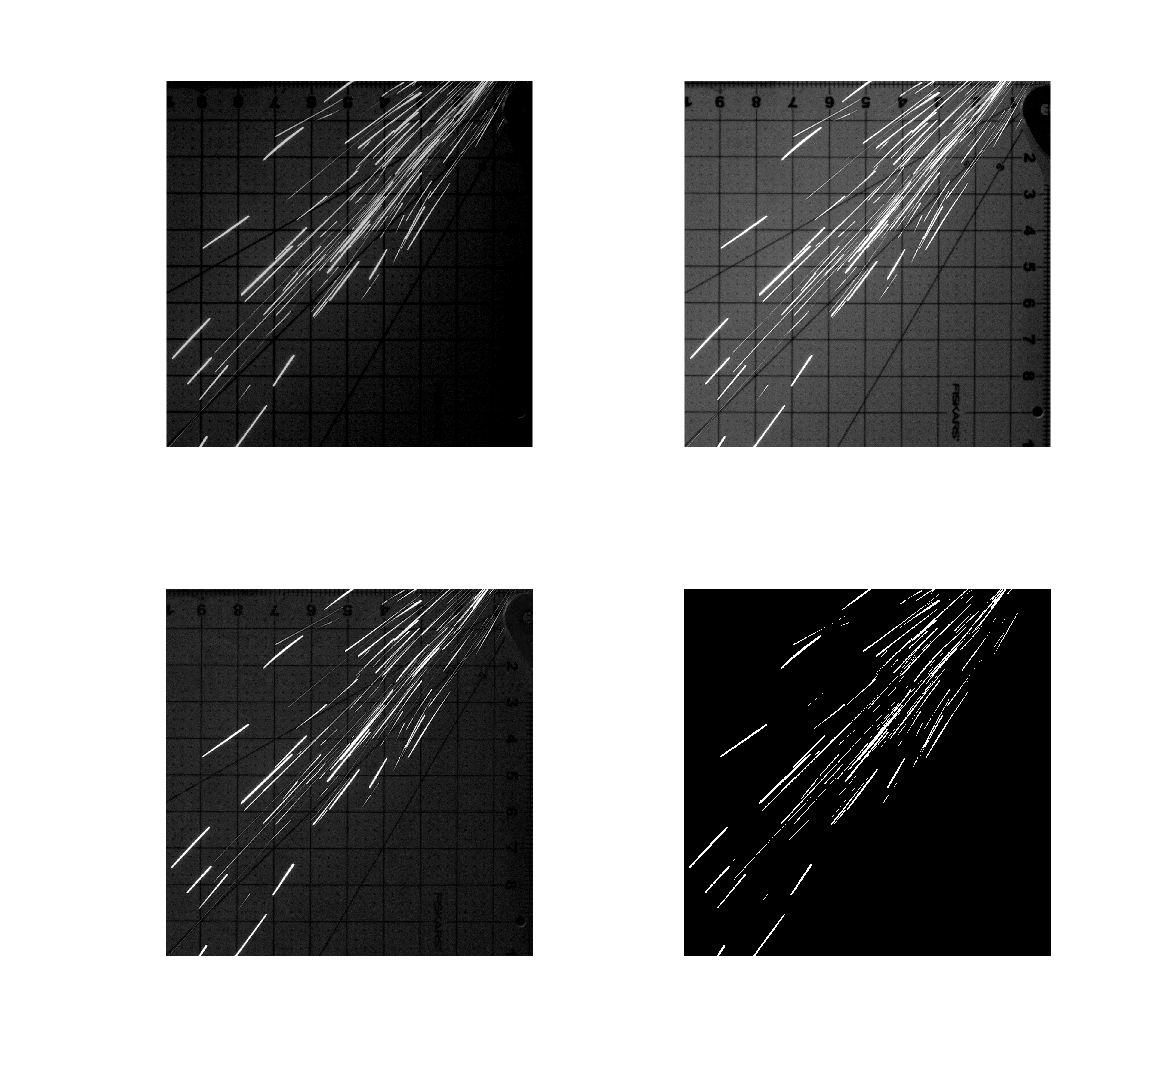

imgInfo = 150×1 struct array with fields:
    Area
    MajorAxisLength


sparkLength = 1×150
  206.6786  136.3371   48.0435  167.1666  209.1675   47.1101  422.9857    6.4291    4.7610  198.1997  338.7834  573.1312   29.9489    4.7610  185.3090  531.2971  104.5995  142.2823  133.2224  234.9742  232.0718    4.7610    5.7735   13.8147   21.4232  143.5584    6.4291   20.5096   18.8767   13.0128


indicies = 1×58
     8     9    14    22    23    24    27    29    30    31    33    34    35    37    38    40    41    46    49    50    53    54    60    63    70    72    87    89    90    93


sparkLength = 1×92
  206.6786  136.3371   48.0435  167.1666  209.1675   47.1101  422.9857  198.1997  338.7834  573.1312   29.9489  185.3090  531.2971  104.5995  142.2823  133.2224  234.9742  232.0718   21.4232  143.5584   20.5096  108.0338  217.6210   63.3978   39.3837   23.1445   41.6275   30.4831   33.7551  128.7759


sparkLenghtMean = 1.1705

sparkArea = 47121

totalArea = 1488400

sparkDensity = 0.0317

sparkInfo = 1×5 cell array
    {[47121]}    {[1488400]}    {[0.0317]}    {'ENGR 140B Lab 1 - Crop - Wroght Iron - 48.jpg'}    {[1.1705]}


tempSpark = 9×5 cell array
    {[65400]}    {[1488400]}    {[0.0439]}    {'ENGR 140B Lab 1 - Crop - Wroght Iron - 40.jpg'}    {[1.3210]}
    {[45411]}    {[1488400]}    {[0.0305]}    {'ENGR 140B Lab 1 - Crop - Wroght Iron - 41.jpg'}    {[1.1576]}
    {[68255]}    {[1488400]}    {[0.0459]}    {'ENGR 140B Lab 1 - Crop - Wroght Iron - 42.jpg'}    {[1.3671]}
    {[57983]}    {[1488400]}    {[0.0390]}    {'ENGR 140B Lab 1 - Crop - Wroght Iron - 43.jpg'}    {[1.2363]}
    {[57773]}    {[1488400]}    {[0.0388]}    {'ENGR 140B Lab 1 - Crop - Wroght Iron - 44.jpg'}    {[1.3884]}
    {[52925]}    {[1488400]}    {[0.0356]}    {'ENGR 140B Lab 1 - Crop - Wroght Iron - 45.jpg'}    {[1.2294]}
    {[39555]}    {[1488400]}    {[0.0266]}    {'ENGR 140B Lab 1 - Crop - Wroght Iron - 46.jpg'}    {[1.2372]}
    {[48084]}    {[1488400]}    {[0.0323]}    {'ENGR 140B Lab 1 - Crop - Wroght Iron - 47.jpg'}    {[1.3974]}
    {[47121]}    {[1488400]}    {[0.0317]}    {'ENGR 140B Lab 1 - Crop - Wroght Iron - 48.jpg

sparkMatrix = 10×5 cell array
    {'sparkArea'}    {'totalArea'}    {'sparkDensity'}    {'image'                                        }    {'sparkLengthMean'}
    {[    65400]}    {[  1488400]}    {[      0.0439]}    {'ENGR 140B Lab 1 - Crop - Wroght Iron - 40.jpg'}    {[         1.3210]}
    {[    45411]}    {[  1488400]}    {[      0.0305]}    {'ENGR 140B Lab 1 - Crop - Wroght Iron - 41.jpg'}    {[         1.1576]}
    {[    68255]}    {[  1488400]}    {[      0.0459]}    {'ENGR 140B Lab 1 - Crop - Wroght Iron - 42.jpg'}    {[         1.3671]}
    {[    57983]}    {[  1488400]}    {[      0.0390]}    {'ENGR 140B Lab 1 - Crop - Wroght Iron - 43.jpg'}    {[         1.2363]}
    {[    57773]}    {[  1488400]}    {[      0.0388]}    {'ENGR 140B Lab 1 - Crop - Wroght Iron - 44.jpg'}    {[         1.3884]}
    {[    52925]}    {[  1488400]}    {[      0.0356]}    {'ENGR 140B Lab 1 - Crop - Wroght Iron - 45.jpg'}    {[         1.2294]}
    {[    39555]}    {[  1488400]}    {[      0.0266]


for j = 13: length(typeDir)
    
    fileFolder = fullfile('Analysis','queue',typeDir(j).name)
    dirOutput = dir(fullfile(fileFolder,'ENGR 140B Lab 1*.jpg'));
    addpath(fileFolder)
    fileNames = {dirOutput.name}'
    tempSpark = []

    for i = 1: length(fileNames)
%     for i = 18: 18
         
    
        imgSrc = imread(fileNames{i})
        imgSrcGray = imadjust(rgb2gray(imgSrc))
        imshow(imgSrcGray)
        rimg = imgSrc(:,:,1)
        gimg = imgSrc(:,:,2)
        bimg = imgSrc(:,:,3)
        imgBrightness = mean(mean(imgSrcGray))
    
        imgBrightnessOffest = (40 - imgBrightness)*1.4
    
        workingImg = uint8(imgSrcGray + imgBrightnessOffest)
    %     imshow(workingImg)
    
        
        rimg = imadjust(rimg)
        gimg = imadjust(gimg)
        bimg = imadjust(bimg)
        
    %     rContrast = max(rimg(:)) - min(rimg(:))
    %     gContrast = max(gimg(:)) - min(gimg(:))
    %     bContrast = max(bimg(:)) - min(bimg(:))
    
    %     if rContrast > gContrast
    %         if rContrast > bCotrast
    %             imgSum = (rimg)
    %         end
    %     end
    %     
    %     if gContrast > rContrast
    %         if gContrast > bCotrast
    %             imgSum =  (gimg)
    %         end
    %     end
    % 
    %     if bContrast > gContrast
    %         if bContrast > rCotrast
    %             imgSum =  (bimg)
    %         end
    %     end
    
        imgSum = sparkMaskMorphBright(workingImg)
    
    %     imgSum = sparkMaskMorph(rimg)&sparkMaskMorph(gimg)&sparkMaskMorph(bimg)    
        
        subplot(2,2,1), imshow(workingImg)
        subplot(2,2,2), imshow(gimg)
        subplot(2,2,3), imshow(bimg)
        subplot(2,2,4), imshow(imgSum)
    
        
    %     imshow(imgSum)
    % 
    %     imshow(rimg)
    %     imshow(gimg)
    %     imshow(bimg)
        
    %     gray = im2gray(imgSrc)  
        % imshow(imgSrc)
        
        % imshow(gray)
    %     grayNorm = imadjust(bimg)
    %     imshow(grayNorm )
        
        
    %     bin = sparkMask(grayNorm);
        
    %     imshow(bin)
        imwrite(imgSum,strcat('BW - ',fileNames{i}),"jpeg")
        imgInfo = regionprops(imgSum,'MajorAxisLength','Area')
    
        sparkLength = [imgInfo.MajorAxisLength;]
        indicies = find(sparkLength<20)
        sparkLength(indicies) = []
        sparkLenghtMean = mean(sparkLength)/120
    
%         imshow(imgSum)
        
    
        sparkArea = sum([imgInfo(:).Area])
        totalArea = numel(imgSum)
        
        sparkDensity = sparkArea / totalArea
    
        sparkInfo = {sparkArea, totalArea, sparkDensity,fileNames{i}, sparkLenghtMean;}
        tempSpark = [tempSpark;sparkInfo]
        sparkMatrix = [sparkMatrix;sparkInfo]
    end
    writecell(tempSpark,sparkDensityData,'Sheet',typeDir(j).name,'Range','A1' )
end

writecell(sparkMatrix,sparkDensityData,'Sheet','all','Range','A1' )